clear;
clc;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J3 = - 2.532435346e-6;
R = 6378.137e3;
a = 7211.54e3;
e = 0.01;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(98.7);
omega   = deg2rad(30);
theta_0 = deg2rad(0);

% Condiciones iniciales
x0  = 0;
y0  = 0;
z0  = 0;
dx0 = 0;
dy0 = 0;
dz0 = 0;

% Identidades trigonométricas
nt = n.*t;
cnt = cos(nt);
snt = sin(nt);
c2nt = cos(2.*nt);
s2nt = sin(2.*nt);
c3nt = cos(3.*nt);
s3nt = sin(3.*nt);
snt2 = snt.^2;
cnt2 = cnt.^2;

si = sin(INC);
ci = cos(INC);
sw = sin(omega);
cw = cos(omega);
s2w = sin(2.*omega);
c2w = cos(2.*omega);
s3w = sin(3.*omega);
c3w = cos(3.*omega);

delta = 2.*(theta_0 - e.*(1 + sqrt(1 - e.^2)).*sin(theta_0));
sd2 = sin(delta./2);
cd2 = cos(delta./2);
theta_c = omega + theta_0 - 2.*e.*sd2;

% Constantes de Kéchichian
f0    =   - e.*cos(theta_c - delta./2);
f(1)  =     - sin(theta_c);
f(2)  =       cos(theta_c);
f(3)  =   - e.*sin(theta_c + delta./2);
f(4)  =     e.*cos(theta_c + delta./2);
f(5)  =   2.*e.*sin(2.*theta_c - delta./2);
f(6)  = - 2.*e.*cos(2.*theta_c - delta./2);
f(7)  =     - sin(2.*theta_c);
fp(7) = - 2.*e.*sin(2.*theta_c + delta./2);
f(8)  =       cos(2.*theta_c);
fp(8) =   2.*e.*cos(2.*theta_c + delta./2);
f(9)  =   3.*e.*sin(3.*theta_c - delta./2);
f(10) = - 3.*e.*cos(3.*theta_c - delta./2);
f(11) =     - sin(3.*theta_c);
f(12) =       cos(3.*theta_c);
f(13) = - 3.*e.*sin(3.*theta_c + delta./2);
f(14) =   3.*e.*cos(3.*theta_c + delta./2);

g0    =   - e.*sin(theta_c - delta./2);
g(1)  =       cos(theta_c);
g(2)  =       sin(theta_c);
g(3)  =     e.*cos(theta_c + delta./2);
g(4)  =     e.*sin(theta_c + delta./2);
g(5)  = - 2.*e.*cos(2.*theta_c - delta./2);
g(6)  = - 2.*e.*sin(2.*theta_c - delta./2);
g(7)  =       cos(2.*theta_c);
gp(7) =   2.*e.*cos(2.*theta_c + delta./2);
g(8)  =       sin(2.*theta_c);
gp(8) =   2.*e.*sin(2.*theta_c + delta./2);
g(9)  = - 3.*e.*cos(3.*theta_c - delta./2);
g(10) = - 3.*e.*sin(3.*theta_c - delta./2);
g(11) =       cos(3.*theta_c);
g(12) =       sin(3.*theta_c);
g(13) =   3.*e.*cos(3.*theta_c + delta./2);
g(14) =   3.*e.*sin(3.*theta_c + delta./2);

ac(2)  =   cw.*f0 +   sw.*g0;
ac(3)  = cw.*f(1) + sw.*g(1);
ac(4)  = cw.*f(2) + sw.*g(2);
ac(5)  = cw.*f(3) + sw.*g(3);
ac(6)  = cw.*f(4) + sw.*g(4);

I(1) = - n.^2.*J3.*R.^3./(2.*a.^2.*(1 - e.^2).^5);
I(2) =   15./4.*si.^3 - 3.*si;
I(3) = - 15./4.*si.^3;

m0    = I(1).*I(2).*f0   + 5.*I(1).*I(2).*e.*(ac(2).*f0 + 1./2.*ac(3).*f(1) + ac(4)./2.*f(2) + ac(5)./2.*f(3) + ac(6)./2.*f(4)) ...
        + 5.*I(1).*I(3).*e.*(ac(5)./2.*f(9) + ac(6)./2.*f(10));
m(1)  = I(1).*I(2).*f(1) + 5.*I(1).*I(2).*e.*(ac(2).*f(1) + ac(3).*f0 - ac(3)./2.*f(4) + ac(4)./2.*f(3) + ac(5)./2.*f(2) - ac(6)./2.*f(1)) ...
        + 5.*I(1).*I(3).*e.*(- ac(3)./2.*f(10) + ac(4)./2.*f(9) - ac(5)./2.*f(12) + ac(6)./2.*f(11));
mp(1) = I(1).*I(2).*f(2) + 5.*I(1).*I(2).*e.*(ac(2).*f(2) + ac(3)./2.*f(3) + ac(4).*f0 + ac(4)./2.*f(4) + ac(5)./2.*f(1) + ac(6)./2.*f(2)) ...
        + 5.*I(1).*I(3).*e.*(ac(3)./2.*f(9) + ac(4)./2.*f(10) + ac(5)./2.*f(11) + ac(6)./2.*f(12));
m(2)  = I(1).*I(2).*f(3) + I(1).*I(3).*f(9) + 5.*I(1).*I(2).*e.*(ac(2).*f(3) + ac(3)./2.*f(2) + ac(4)./2.*f(1) + ac(5).*f0) ...
        + 5.*I(1).*I(3).*e.*(ac(2).*f(9) - ac(3)./2.*f(12) + ac(4)./2.*f(11) - ac(5)./2.*f(14) + ac(6)./2.*f(13));
mp(2) = I(1).*I(2).*f(4) + I(1).*I(3).*f(10) + 5.*I(1).*I(2).*e.*(ac(2).*f(4) - ac(3)./2.*f(1) + ac(4)./2.*f(2) + ac(6).*f0) ...
        + 5.*I(1).*I(3).*e.*(ac(2).*f(10) + ac(3)./2.*f(11) + ac(4)./2.*f(12) + ac(5)./2.*f(13) + ac(6)./2.*f(14));
m(3)  = I(1).*I(3).*f(11) + 5.*I(1).*I(2).*e.*(ac(3)./2.*f(4) + ac(4)./2.*f(3) + ac(5)./2.*f(2) + ac(6)./2.*f(1)) ...
        + 5.*I(1).*I(3).*e.*(ac(2).*f(11) + ac(3)./2.*f(10) - ac(3)./2.*f(14) + ac(4)./2.*f(9) + ac(4)./2.*f(13));
mp(3) = I(1).*I(3).*f(12) + 5.*I(1).*I(2).*e.*(-ac(3)./2.*f(3) + ac(4)./2.*f(4) - ac(5)./2.*f(1) + ac(6)./2.*f(2)) ...
        + 5.*I(1).*I(3).*e.*(ac(2).*f(12) - ac(3)./2.*f(9) + ac(3)./2.*f(13) + ac(4)./2.*f(10) + ac(4)./2.*f(14));
m(4)  = I(1).*I(3).*f(13) + 5.*I(1).*I(2).*e.*(ac(5)./2.*f(4) + ac(6)./2.*f(3)) ...
        + 5.*I(1).*I(3).*e.*(ac(2).*f(13) + ac(3)./2.*f(12) + ac(4)./2.*f(11) + ac(5)./2.*f(10) + ac(6)./2.*f(9));
mp(4) = I(1).*I(3).*f(14) + 5.*I(1).*I(2).*e.*(-ac(5)./2.*f(3) + ac(6)./2.*f(4)) ...
        + 5.*I(1).*I(3).*e.*(ac(2).*f(14) - ac(3)./2.*f(11) + ac(4)./2.*f(12) - ac(5).*f(9) + ac(6)./2.*f(10));
m(5)  = 5.*I(1).*I(3).*e.*( ac(3)./2.*f(14) + ac(4)./2.*f(13) + ac(5)./2.*f(12) + ac(6)./2.*f(11));
mp(5) = 5.*I(1).*I(3).*e.*(-ac(3)./2.*f(13) + ac(4)./2.*f(14) - ac(5)./2.*f(11) + ac(6)./2.*f(12));
m(6)  = 5.*I(1).*I(3).*e.*( ac(5)./2.*f(14) + ac(6)./2.*f(13));
mp(6) = 5.*I(1).*I(3).*e.*(-ac(5)./2.*f(13) + ac(6)./2.*f(14));

p(1) = - n.^2.*J3.*R.^3./(a.^2.*(1 - e.^2).^5);
p(2) =   6.*si - 15./2.*si.^3;
p(3) =   5./2.*si.^3;

r0    = p(1).*p(2).*g0 + 5.*p(1).*p(2).*e.*(ac(2).*g0 + ac(3)./2.*g(1) + ac(4)./2.*g(2) + ac(5)./2.*g(3) + ac(6)./2.*g(4)) ...
        + 5.*p(1).*p(3).*e.*(ac(5)./2.*g(9) + ac(6)./2.*g(10));
r(1)  = p(1).*p(2).*g(1) + 5.*p(1).*p(2).*e.*(ac(2).*g(1) + ac(3).*g0 - ac(3)./2.*g(4) + ac(4)./2.*g(3) + ac(5)./2.*g(2) - ac(6)./2.*g(1)) ...
        + 5.*p(1).*p(3).*e.*(-ac(3)./2.*g(10) + ac(4)./2.*g(9) - ac(5)./2.*g(12) + ac(6)./2.*g(11));
rp(1) = p(1).*p(2).*g(2) + 5.*p(1).*p(2).*e.*(ac(2).*g(2) + ac(3)./2.*g(3) + ac(4).*g0 + ac(4)./2.*g(4) + ac(5)./2.*g(1) + ac(6)./2.*g(2)) ...
        + 5.*p(1).*p(3).*e.*(ac(3)./2.*g(9) + ac(4)./2.*g(10) + ac(5)./2.*g(11) + ac(6)./2.*g(12));
r(2)  = p(1).*p(2).*g(3) + p(1).*p(3).*g(9) + 5.*p(1).*p(2).*e.*(ac(2).*g(3) + ac(3)./2.*g(2) + ac(4)./2.*g(1) + ac(5).*g0) ...
        + 5.*p(1).*p(3).*e.*(ac(2).*g(9) - ac(3)./2.*g(12) + ac(4)./2.*g(11) - ac(5)./2.*g(14) + ac(6)./2.*g(13));
rp(2) = p(1).*p(2).*g(4) + p(1).*p(3).*g(10) + 5.*p(1).*p(2).*e.*(ac(2).*g(4) - ac(3)./2.*g(1) + ac(4)./2.*g(2) + ac(6).*g0) ...
        + 5.*p(1).*p(3).*e.*(ac(2).*g(10) + ac(3)./2.*g(11) + ac(4)./2.*g(12) + ac(5)./2.*g(13) + ac(6)./2.*g(14));
r(3)  = p(1).*p(3).*g(11) + 5.*p(1).*p(2).*e.*(ac(3)./2.*g(4) + ac(4)./2.*g(3) + ac(5)./2.*g(2) + ac(6)./2.*g(1)) ...
        + 5.*p(1).*p(3).*e.*(ac(2).*g(11) + ac(3)./2.*g(10) - ac(3)./2.*g(14) + ac(4)./2.*g(9) + ac(4)./2.*g(13));
rp(3) = p(1).*p(3).*g(12) + 5.*p(1).*p(2).*e.*(-ac(3)./2.*g(3) + ac(4)./2.*g(4) - ac(5)./2.*g(1) + ac(6)./2.*g(2)) ...
        + 5.*p(1).*p(3).*e.*(ac(2).*g(12) - ac(3)./2.*g(9) + ac(3)./2.*g(13) + ac(4)./2.*g(10) + ac(4)./2.*g(14));
r(4)  = p(1).*p(3).*g(13) + 5.*p(1).*p(2).*e.*(ac(5)./2.*g(4) + ac(6)./2.*g(3)) ...
        + 5.*p(1).*p(3).*e.*(ac(2).*g(13) + ac(3)./2.*g(12) + ac(4)./2.*g(11) + ac(5)./2.*g(10) + ac(6)./2.*g(9));
rp(4) = p(1).*p(3).*g(14) + 5.*p(1).*p(2).*e.*(-ac(5)./2.*g(3) + ac(6)./2.*g(4)) ...
        + 5.*p(1).*p(3).*e.*(ac(2).*g(14) - ac(3)./2.*g(11) + ac(4)./2.*g(12) - ac(5)./2.*g(9) + ac(6)./2.*g(10));
r(5)  = 5.*p(1).*p(3).*e.*( ac(3)./2.*g(14) + ac(4)./2.*g(13) + ac(5)./2.*g(12) + ac(6)./2.*g(11));
rp(5) = 5.*p(1).*p(3).*e.*(-ac(3)./2.*g(13) + ac(4)./2.*g(13) - ac(5)./2.*g(11) + ac(6)./2.*g(12));
r(6)  = 5.*p(1).*p(3).*e.*( ac(5)./2.*g(14) + ac(6)./2.*g(13));
rp(6) = 5.*p(1).*p(3).*e.*(-ac(5)./2.*g(13) + ac(6)./2.*g(14));

tc(1) = - n.^2.*J3.*R.^3./(2.*a.^2.*(1 - e.^2).^5);
tc(2) =   15./2.*si.^2.*ci - 3.*ci;
tc(3) = - 15./2.*si.^2.*ci;

u0    = tc(1).*tc(2) + 5.*tc(1).*tc(2).*e.*ac(2) + 5.*tc(1).*tc(3).*e.*(ac(3)./2.*f(5) + ac(4)./2.*f(6) + ac(5)./2.*f(7) + ac(6)./2.*f(8));
u(1)  = tc(1).*tc(3).*f(5) + 5.*tc(1).*tc(2).*e.*ac(3) + ...
        5.*tc(1).*tc(3).*e.*(ac(2).*f(5) - ac(3)./2.*f(8) + ac(4)./2.*f(7) + ac(5)./2.*f(6) - ac(6)./2.*f(5) - ac(3)./2.*fp(8) - ac(5)./2.*fp(8) + ac(6)./2.*fp(7));
up(1) = tc(1).*tc(3).*f(6) + 5.*tc(1).*tc(2).*e.*ac(4) + ...
        5.*tc(1).*tc(3).*e.*(ac(2).*f(6) + ac(3)./2.*f(7) + ac(4)./2.*f(8) + ac(5)./2.*f(5) + ac(6)./2.*f(6) + ac(6)./2.*fp(8) + ac(5)./2.*fp(7) + ac(3)./2.*fp(7));
u(2)  = tc(1).*tc(3).*f(7) + 5.*tc(1).*tc(2).*e.*ac(5) + 5.*tc(1).*tc(3).*e.*(ac(2).*f(7) + ac(3)./2.*f(6) + ac(4)./2.*f(5) + ac(4)./2.*fp(7));
up(2) = tc(1).*tc(3).*f(8) + 5.*tc(1).*tc(2).*e.*ac(6) + 5.*tc(1).*tc(3).*e.*(ac(2).*f(8) - ac(3)./2.*f(5) + ac(4)./2.*f(6) + ac(4)./2.*fp(8));
u(3)  = 5.*tc(1).*tc(3).*e.*(  ac(3)./2.*f(8) + ac(4)./2.*f(7) + ac(5)./2.*f(6) + ac(6)./2.*f(5) + ac(2).*fp(7) + ac(3)./2.*fp(8));
up(3) = 5.*tc(1).*tc(3).*e.*(- ac(3)./2.*f(7) + ac(4)./2.*f(8) - ac(5)./2.*f(5) + ac(6)./2.*f(6) + ac(2).*fp(8) + ac(3)./2.*fp(7));
u(4)  = 5.*tc(1).*tc(3).*e.*(  ac(5)./2.*f(8) + ac(6)./2.*f(7) + ac(4)./2.*fp(7));
up(4) = 5.*tc(1).*tc(3).*e.*(- ac(5)./2.*f(7) + ac(6)./2.*f(8) + ac(4)./2.*fp(8));
u(5)  = 5.*tc(1).*tc(3).*e.*(ac(6)./2.*fp(7) + ac(5)./2.*fp(8));
up(5) = 5.*tc(1).*tc(3).*e.*(ac(6)./2.*fp(8) - ac(5)./2.*fp(7));

K1  = dy0 + 2.*n.*x0 + sum(arrayfun(@(j) m(j)./(j.*n) , 1:6));
Kp1 = y0 - 2.*dx0./n + 4.*m0./n.^2 ...
      - sum(arrayfun(@(j) 2./(j.*n.^2).*(2.*mp(j)./j + r(j)) , 2:6)) ...
      + sum(arrayfun(@(j) mp(j)./(j.^2.*n.^2) , 1:6)) - 2.*(2.*mp(1) + r(1))./n.^2;

% Solución analítica
xJ3B = (-(1536.*a.^2.*n - 1152.*a.^2.*n.*cos(n.*t) - 7680.*a.^2.*e.^2.*n + 15360.*a.^2.*e.^4.*n - 15360.*a.^2.*e.^6.*n + 7680.*a.^2.*e.^8.*n - 1536.*a.^2.*e.^10.*n + 5760.*a.^2.*e.^2.*n.*cos(n.*t) - 11520.*a.^2.*e.^4.*n.*cos(n.*t) + 11520.*a.^2.*e.^6.*n.*cos(n.*t) - 5760.*a.^2.*e.^8.*n.*cos(n.*t) + 1152.*a.^2.*e.^10.*n.*cos(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*x0 + (-(384.*sin(n.*t).*a.^2 - 1920.*sin(n.*t).*a.^2.*e.^2 + 3840.*sin(n.*t).*a.^2.*e.^4 - 3840.*sin(n.*t).*a.^2.*e.^6 + 1920.*sin(n.*t).*a.^2.*e.^8 - 384.*sin(n.*t).*a.^2.*e.^10)./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*dx0 + (-(768.*a.^2 - 768.*a.^2.*cos(n.*t) - 3840.*a.^2.*e.^2 + 7680.*a.^2.*e.^4 - 7680.*a.^2.*e.^6 + 3840.*a.^2.*e.^8 - 768.*a.^2.*e.^10 + 3840.*a.^2.*e.^2.*cos(n.*t) - 7680.*a.^2.*e.^4.*cos(n.*t) + 7680.*a.^2.*e.^6.*cos(n.*t) - 3840.*a.^2.*e.^8.*cos(n.*t) + 768.*a.^2.*e.^10.*cos(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*dy0 + ((1800.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(INC) - 120.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) - 5400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(omega) - 120.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) + 360.*R.^3.*n.*sin(3.*INC).*cos(omega).*sin(theta_0) + 360.*R.^3.*n.*sin(3.*INC).*cos(theta_0).*sin(omega) + 108.*R.^3.*e.*n.*sin(INC).*sin(omega) - 600.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega) + 360.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) + 360.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) + 540.*R.^3.*e.*n.*sin(3.*INC).*sin(omega) + 16200.*R.^3.*e.^3.*n.*sin(INC).*sin(omega) + 72.*R.^3.*n.*sin(INC).*cos(omega).*sin(theta_0) + 72.*R.^3.*n.*sin(INC).*cos(theta_0).*sin(omega) + 720.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) + 720.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) + 360.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) + 360.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) + 630.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) + 630.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) - 4530.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(omega).*sin(theta_0) - 4410.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(theta_0).*sin(omega) - 630.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(INC).*sin(theta_0) - 810.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(INC).*sin(omega) - 630.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(INC).*cos(theta_0) - 810.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(INC).*cos(omega) + 14400.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(INC).*sin(omega) + 28800.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(INC).*cos(omega) - 1800.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(INC).*sin(omega) - 1800.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(INC).*cos(omega) - 180.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 108.*R.^3.*e.*n.*cos(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.*sin(n.*t).*sin(INC).*cos(omega) + 475.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t) + 725.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t) - 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t) - 200.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t) + 72.*R.^3.*e.*n.^2.*t.*sin(INC).*cos(omega) + 135.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t).*sin(INC) - 315.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) - 315.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 45.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 45.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 45.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 120.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) - 120.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) - 210.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) - 210.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) + 210.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(theta_0) - 210.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(omega) + 210.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(theta_0) - 210.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(omega) - 1665.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) - 1665.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) - 4800.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) - 9600.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) + 2700.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) + 2700.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) - 603.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(INC) - 603.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(INC) + 600.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(omega) + 600.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(omega) + 1080.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) + 1080.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) + 180.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(INC) + 180.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(INC) - 135.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) + 45.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 540.*R.^3.*e.*n.*sin(3.*INC).*cos(n.*t).*sin(omega) + 270.*R.^3.*e.*n.*sin(3.*INC).*sin(n.*t).*cos(omega) - 12000.*R.^3.*e.^3.*n.*cos(n.*t).*sin(INC).*sin(omega) - 4200.*R.^3.*e.^3.*n.*sin(n.*t).*sin(INC).*cos(omega) - 4200.*R.^3.*e.^3.*n.*cos(2.*n.*t).*sin(INC).*sin(omega) - 4200.*R.^3.*e.^3.*n.*sin(2.*n.*t).*sin(INC).*cos(omega) - 72.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 72.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 36.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 360.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(omega) - 45.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t) + 105.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t) + 105.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t) + 15.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t) + 15.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) + 15.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 144.*R.^3.*e.*n.*cos(2.*theta_0).*sin(INC).*sin(omega) + 144.*R.^3.*e.*n.*sin(2.*theta_0).*sin(INC).*cos(omega) + 12150.*R.^3.*e.^2.*n.*sin(INC).*cos(omega).*sin(theta_0) + 6030.*R.^3.*e.^2.*n.*sin(INC).*cos(theta_0).*sin(omega) - 36.*R.^3.*n.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 555.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) + 555.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) - 900.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) - 900.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) + 201.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0) + 201.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega) - 360.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) - 360.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) - 60.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0) - 60.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega) + 45.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 15.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) + 4000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(n.*t).*sin(omega) + 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega) - 1425.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(n.*t).*sin(INC) - 2175.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(n.*t).*sin(INC) + 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*n.*t).*sin(omega) + 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega) + 600.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC) + 600.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 360.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 360.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 180.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t) + 126.*R.^3.*e.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega) - (255.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t))./2 + (195.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t))./2 + (195.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t))./2 - 60.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - (195.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t))./2 - 60.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + (375.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t))./2 - 60.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(2.*n.*t) + (375.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t))./2 + (165.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t))./2 + (165.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t))./2 + (165.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t))./2 - (15.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t))./2 - (15.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t))./2 - (15.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t))./2 + 30.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 30.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 30.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(4.*n.*t) - (245.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*sin(theta_0))./2 + (305.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*cos(theta_0))./2 + 1130.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 700.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - (245.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*cos(theta_0))./2 + 1130.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 120.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t).*sin(INC) + 1440.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) + 1440.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 4575.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 2025.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 9375.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 1725.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 3075.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 3075.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 230.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t).*sin(theta_0) - 230.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t).*cos(theta_0) - 1010.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 1010.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 230.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t).*cos(theta_0) - 1010.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 210.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC) - (225.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(n.*t).*sin(INC))./2 + 210.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC) + (1005.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(n.*t).*sin(INC))./2 + 210.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) + (1005.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC))./2 + 575.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*sin(omega) + 625.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*cos(omega) + 575.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*cos(omega) - 300.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t).*sin(INC) - 1050.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 1050.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + (285.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*n.*t).*sin(theta_0))./2 + (285.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t).*cos(theta_0))./2 + 90.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 90.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + (285.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t).*cos(theta_0))./2 + 90.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 360.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC) + 360.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) + 360.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(3.*n.*t).*sin(omega) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*n.*t).*cos(omega) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(3.*n.*t).*cos(omega) + 675.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 345.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(4.*n.*t).*sin(INC) - 345.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t).*sin(INC) - 345.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) - 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(2.*n.*t).*sin(omega) - 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(2.*n.*t).*cos(omega) - 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(2.*n.*t).*cos(omega) - 300.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(4.*n.*t).*sin(INC) - 600.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t).*sin(INC) - 600.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC) - 150.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) - 600.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - 150.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + (495.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(3.*n.*t).*sin(INC))./2 + (495.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + (495.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC))./2 + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(3.*n.*t).*sin(omega) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*n.*t).*cos(omega) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(3.*n.*t).*cos(omega) + 675.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 105.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(4.*n.*t).*sin(INC) - 105.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t).*sin(INC) - 105.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) - 42.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(5.*n.*t).*sin(INC) - 42.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t).*sin(INC) - 42.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(5.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(3.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(4.*n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(5.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t) + (255.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t))./2 + 60.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + (195.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t))./2 - (165.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t))./2 + (15.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t))./2 - 30.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - (305.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*sin(theta_0))./2 - 700.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 120.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 12825.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 1725.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 230.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t).*sin(theta_0) + 1010.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 210.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC) + (225.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(n.*t).*sin(INC))./2 - 625.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*sin(omega) + 300.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) - (285.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*n.*t).*sin(theta_0))./2 - 90.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 360.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC) + 345.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t).*sin(INC) + 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(2.*n.*t).*sin(omega) + 300.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t).*sin(INC) + 600.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC) - (495.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC) + 105.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t).*sin(INC) + 42.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t).*sin(INC) + 105.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t).*sin(INC) + 225.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t).*sin(INC) + 105.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t).*sin(INC) - 630.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega) + 12600.*R.^3.*e.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega) + 7200.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) - 36.*R.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 108.*R.^3.*e.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 126.*R.^3.*e.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 108.*R.^3.*e.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 36.*R.^3.*e.*n.*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 36.*R.^3.*e.*n.*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) - 36.*R.^3.*e.*n.*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 10380.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 4260.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 1770.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 1770.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 1770.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 1770.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 630.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*sin(omega) - 14400.*R.^3.*e.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega) + 40.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t) - 480.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 480.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t) + 575.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 1025.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 1025.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) - 70.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(2.*n.*t) + (75.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(n.*t))./2 - 70.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - (335.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(n.*t))./2 - 70.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(2.*n.*t) - (335.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(n.*t))./2 + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t) + 350.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 350.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t) - 120.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t) - 120.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) - 120.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 115.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(4.*n.*t) + 115.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t) + 115.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(4.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(4.*n.*t) + 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(2.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t) + 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t) + 50.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(4.*n.*t) + 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(2.*n.*t) + 50.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(n.*t) - (165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(3.*n.*t))./2 - (165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t))./2 - (165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(3.*n.*t))./2 - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 35.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(4.*n.*t) + 35.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t) + 35.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(4.*n.*t) + 14.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(5.*n.*t) + 14.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t) + 14.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(5.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(5.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(3.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(5.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(4.*n.*t) - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t) - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(4.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(5.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(5.*n.*t) + 360.*R.^3.*e.^2.*n.^2.*t.*sin(INC).*cos(omega).*cos(theta_0) + 36.*R.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 36.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 36.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 126.*R.^3.*e.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 36.*R.^3.*e.*n.*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 14550.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 1770.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 40.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 575.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t) + 70.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t) - (75.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(n.*t))./2 - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t) + 120.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t) - 115.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t) - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t) - 200.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t) + (165.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t))./2 + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t) - 35.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t) - 14.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t) - 35.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t) - 75.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t) - 35.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t) - 8640.*R.^3.*e.^2.*n.^2.*t.*sin(INC).*sin(omega).*sin(theta_0) - 4200.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega) + 900.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*cos(n.*t).*sin(INC) - 180.*R.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 540.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 630.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 540.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + (765.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC))./2 - (585.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC))./2 - (585.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC))./2 - 180.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) - 180.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 180.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 180.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC) + (585.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t).*sin(INC))./2 + 180.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC) - (1125.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC))./2 + 180.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - (1125.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC))./2 - (495.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - (495.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC))./2 - (495.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC))./2 + (45.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC))./2 + (45.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + (45.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC))./2 - 90.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(4.*n.*t).*sin(INC) - 90.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*sin(INC) - 90.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) + 4420.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 4300.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 110.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + (735.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0))./2 - (915.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0))./2 - 510.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 660.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + (735.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0))./2 - 510.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 13725.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 6075.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 28125.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 110.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 110.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 110.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 690.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(2.*n.*t).*sin(INC).*sin(theta_0) + 690.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC).*cos(theta_0) + 1590.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 1590.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 690.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC).*cos(theta_0) + 1590.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 1725.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 1875.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 1725.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - (855.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).*sin(theta_0))./2 - (855.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC).*cos(theta_0))./2 - 270.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 270.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - (855.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC).*cos(theta_0))./2 - 270.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) - 675.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 675.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 675.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 4200.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 4200.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 4200.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 675.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 675.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 675.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 4800.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*sin(omega) - 900.*R.^3.*e.^3.*n.^2.*t.*sin(3.*omega).*sin(n.*t).*sin(INC) + 1800.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(omega).*cos(theta_0) + 180.*R.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 180.*R.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 180.*R.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 630.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - (765.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC))./2 + 180.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) - 180.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC) - (585.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC))./2 + (495.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - (45.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC))./2 + 90.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t).*sin(INC) - 5330.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + (915.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0))./2 + 660.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 38475.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 110.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0) - 690.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(2.*n.*t).*sin(INC).*sin(theta_0) - 1590.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 1875.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + (855.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).*sin(theta_0))./2 + 270.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + 675.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) - 4200.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 675.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) - 126.*R.^3.*e.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega) + 2880.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(omega).*sin(theta_0) - 21600.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*sin(INC).*sin(omega) + 120.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*sin(theta_0) - 1050.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 120.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*sin(theta_0) + 120.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*cos(theta_0) - 1050.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 1050.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) + 3300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 5700.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) - 900.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^2.*t.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 1500.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*sin(omega) - 1500.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*sin(omega) - 1500.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*cos(omega) - 54.*R.^3.*e.*n.^2.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 4950.*R.^3.*e.^2.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) + 54.*R.^3.*e.*n.^2.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.^2.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.^2.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 9450.*R.^3.*e.^2.*n.^2.*t.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 8730.*R.^3.*e.^2.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 5670.*R.^3.*e.^2.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) + 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) + 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) - 270.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 2130.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 360.*R.^3.*e.^2.*n.^2.*t.*cos(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) - 1710.*R.^3.*e.^2.*n.^2.*t.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 8100.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 4500.*R.^3.*e.^3.*n.^2.*t.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 270.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 270.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 270.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 2670.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 2430.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 2370.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 360.*R.^3.*e.^2.*n.^2.*t.*cos(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) + 1710.*R.^3.*e.^2.*n.^2.*t.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 360.*R.^3.*e.^2.*n.^2.*t.*sin(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 360.*R.^3.*e.^2.*n.^2.*t.*sin(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) + 1710.*R.^3.*e.^2.*n.^2.*t.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 1710.*R.^3.*e.^2.*n.^2.*t.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 9900.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 18900.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 17100.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 4500.*R.^3.*e.^3.*n.^2.*t.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 4500.*R.^3.*e.^3.*n.^2.*t.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 4500.*R.^3.*e.^3.*n.^2.*t.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 120.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*cos(theta_0) + 1050.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 2700.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 900.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*cos(omega))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*J3;
    term1 = dx0 ./ n .* snt + x0 .* cnt;
    term2 = (r0 + 2.*n.*K1) .* (1 - cnt) ./ n.^2;
    term3 = 2.*m0 ./ n .* (n.*t - snt) ./ n;
    term4 = (2.*mp(1) + r(1)) .* snt ./ (2.*n.^2);
    term5 = -(2.*mp(1) + r(1)) .* t .* cnt ./ (2.*n);
    term6 = -(2.*m(1) - rp(1)) .* t .* snt ./ (2.*n);
    term7 = zeros(size(t));
    term8 = zeros(size(t));
    for j = 2:6
    term7 = term7 + (2.*mp(j)./j +  r(j)).*(j.*snt - sin(j.*n.*t))./(n.^2.*(j.^2 - 1));
    term8 = term8 + (2.* m(j)./j - rp(j)).*(  cnt - cos(j.*n.*t))./(n.^2.*(j.^2 - 1));
    end
xJ3K = term1 + term2 + term3 + term4 + term5 + term6 + term7 - term8;


xdotJ3B = (-(1152.*a.^2.*n.^2.*sin(n.*t) - 5760.*a.^2.*e.^2.*n.^2.*sin(n.*t) + 11520.*a.^2.*e.^4.*n.^2.*sin(n.*t) - 11520.*a.^2.*e.^6.*n.^2.*sin(n.*t) + 5760.*a.^2.*e.^8.*n.^2.*sin(n.*t) - 1152.*a.^2.*e.^10.*n.^2.*sin(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*x0 + (-(384.*a.^2.*n.*cos(n.*t) - 1920.*a.^2.*e.^2.*n.*cos(n.*t) + 3840.*a.^2.*e.^4.*n.*cos(n.*t) - 3840.*a.^2.*e.^6.*n.*cos(n.*t) + 1920.*a.^2.*e.^8.*n.*cos(n.*t) - 384.*a.^2.*e.^10.*n.*cos(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*dx0 + (-(768.*a.^2.*n.*sin(n.*t) - 3840.*a.^2.*e.^2.*n.*sin(n.*t) + 7680.*a.^2.*e.^4.*n.*sin(n.*t) - 7680.*a.^2.*e.^6.*n.*sin(n.*t) + 3840.*a.^2.*e.^8.*n.*sin(n.*t) - 768.*a.^2.*e.^10.*n.*sin(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*dy0 + ((360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(omega) + 72.*R.^3.*e.*n.^2.*sin(INC).*cos(omega) - 45.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t) + 45.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t) + 360.*R.^3.*e.^2.*n.^2.*sin(INC).*cos(omega).*cos(theta_0) + 108.*R.^3.*n.^2.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 108.*R.^3.*n.^2.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 105.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 105.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t) + 45.*R.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 45.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) - 45.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t) - 45.*R.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) - 8640.*R.^3.*e.^2.*n.^2.*sin(INC).*sin(omega).*sin(theta_0) - 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega) - 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(n.*t).*sin(INC) + 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*n.*t).*cos(omega) + 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*n.*t).*sin(INC) - 675.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(3.*n.*t).*sin(INC) + 800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*sin(omega) + 1275.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(n.*t).*sin(INC) - 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*n.*t).*sin(omega) - 1200.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(3.*n.*t).*sin(INC) + 1800.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(omega).*cos(theta_0) + 540.*R.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 540.*R.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 72.*R.^3.*e.*n.^2.*cos(n.*t).*sin(INC).*cos(omega) + 2880.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(omega).*sin(theta_0) - 21600.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(INC).*sin(omega) + 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t) + 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*n.*t) + 234.*R.^3.*e.*n.^2.*sin(n.*t).*sin(INC).*sin(omega) + 135.*R.^3.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t).*sin(INC) - 135.*R.^3.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 425.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t) - 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*n.*t) + 315.*R.^3.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) + 315.*R.^3.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 135.*R.^3.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) + 135.*R.^3.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) + 135.*R.^3.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) + 135.*R.^3.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega) + 8400.*R.^3.*e.^3.*n.^2.*cos(n.*t).*sin(INC).*cos(omega) - 8400.*R.^3.*e.^3.*n.^2.*cos(2.*n.*t).*sin(INC).*cos(omega) + 7200.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) + 1170.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(n.*t).*sin(omega) - 2400.*R.^3.*e.^3.*n.^2.*sin(n.*t).*sin(INC).*sin(omega) + 8400.*R.^3.*e.^3.*n.^2.*sin(2.*n.*t).*sin(INC).*sin(omega) + 360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + (765.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC))./2 - 360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 360.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC) + (585.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t).*sin(INC))./2 - (1485.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + (135.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC))./2 - 360.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*sin(INC) - 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - (195.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0))./2 - 2370.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 220.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) + 1380.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(2.*n.*t).*sin(INC).*cos(theta_0) + 3180.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 6375.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - (2565.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).*cos(theta_0))./2 - 810.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) - 2025.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 8400.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 2025.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*sin(n.*t) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(3.*omega).*cos(n.*t) + 810.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 360.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 810.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + (585.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC))./2 + (585.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC))./2 - (765.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC))./2 + 360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 360.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 360.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 360.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC) + (1125.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC))./2 - 360.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + (1125.*R.^3.*e.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC))./2 - 360.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC) - (585.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC))./2 + (1485.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC))./2 + (1485.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC))./2 + (1485.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC))./2 - (135.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - (135.*R.^3.*e.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC))./2 - (135.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + 360.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t).*sin(INC) + 360.*R.^3.*e.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) + 360.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*sin(INC) - 2660.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 1990.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 1930.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - (1455.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0))./2 + 2220.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + (195.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0))./2 - (1455.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0))./2 + 2370.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 2220.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 3825.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 19575.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 11025.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 220.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) - 220.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) - 220.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 1380.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(2.*n.*t).*sin(INC).*sin(theta_0) - 3180.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) - 1380.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*cos(2.*n.*t).*sin(INC).*sin(theta_0) - 1380.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(2.*n.*t).*sin(INC).*cos(theta_0) - 3180.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 3180.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 6225.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 6375.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 6225.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + (2565.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*n.*t).*sin(INC).*sin(theta_0))./2 + 810.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + (2565.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*cos(3.*n.*t).*sin(INC).*sin(theta_0))./2 + (2565.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).*cos(theta_0))./2 + 810.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) + 810.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + 2025.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) + 2025.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 8400.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) - 8400.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 8400.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + 2025.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) + 2025.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) + 630.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*sin(omega) + 630.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*cos(omega) - 14400.*R.^3.*e.^3.*n.^3.*t.*cos(n.*t).*sin(INC).*sin(omega) - 12600.*R.^3.*e.^3.*n.^3.*t.*sin(n.*t).*sin(INC).*cos(omega) - (255.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t))./2 - 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - (195.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t))./2 + (495.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t))./2 - (45.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t))./2 + 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + (65.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*cos(theta_0))./2 + 1750.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 120.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t).*sin(INC) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 825.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) - 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t).*cos(theta_0) - 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 420.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC) - (225.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(5.*theta_0).*cos(n.*t).*sin(INC))./2 + 2125.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*cos(omega) - 300.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t).*sin(INC) + (855.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*n.*t).*cos(theta_0))./2 + 270.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 1080.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(3.*n.*t).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC) - 1380.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(4.*n.*t).*sin(INC) - 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*cos(2.*n.*t).*cos(omega) - 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(4.*n.*t).*sin(INC) - 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC) + (1485.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(5.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*cos(3.*n.*t).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC) - 420.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(5.*theta_0).*cos(4.*n.*t).*sin(INC) - 210.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(5.*theta_0).*cos(5.*n.*t).*sin(INC) - 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(5.*n.*t).*sin(INC) - 675.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(6.*theta_0).*cos(3.*n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(6.*theta_0).*cos(4.*n.*t).*sin(INC) - 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(6.*theta_0).*cos(5.*n.*t).*sin(INC) + 36.*R.^3.*n.^3.*t.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 36.*R.^3.*n.^3.*t.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 36.*R.^3.*n.^3.*t.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - (195.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t))./2 - (195.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t))./2 + (255.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t))./2 + 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - (375.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t))./2 + 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(2.*n.*t) - (375.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t))./2 + 120.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + (195.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t))./2 - (495.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t))./2 - (495.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t))./2 - (495.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t))./2 + (45.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t))./2 + (45.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t))./2 + (45.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t))./2 - 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(4.*n.*t) - 120.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + (485.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*sin(theta_0))./2 - 2180.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) - (65.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*sin(theta_0))./2 + (485.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*cos(theta_0))./2 - 1750.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 2180.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 1440.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 1440.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 120.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) - 1275.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 6525.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 2175.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 2175.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 825.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) + 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t).*sin(theta_0) + 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) + 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t).*sin(theta_0) + 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t).*cos(theta_0) + 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 420.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC) - (1005.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(n.*t).*sin(INC))./2 - 420.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) - (1005.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC))./2 - 420.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC) + (225.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(5.*theta_0).*cos(n.*t).*sin(INC))./2 - 2075.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*sin(omega) - 2125.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*sin(omega) - 2075.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*cos(omega) + 1050.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) + 1050.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - (855.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t).*sin(theta_0))./2 - 270.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) - (855.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t).*sin(theta_0))./2 - (855.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*n.*t).*cos(theta_0))./2 - 270.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) - 270.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega) - 1080.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 1080.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) - 1080.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(3.*n.*t).*cos(omega) - 2025.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC) - 2025.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) - 2025.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC) + 1380.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t).*sin(INC) + 1380.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) + 1380.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t).*sin(INC) + 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(2.*n.*t).*sin(omega) + 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(2.*n.*t).*sin(omega) + 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*sin(2.*n.*t).*cos(omega) + 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC) + 150.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + 150.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC) - (1485.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - (1485.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC))./2 - (1485.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t).*sin(INC))./2 - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*sin(3.*n.*t).*cos(omega) - 2025.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC) - 2025.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) - 2025.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC) + 420.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t).*sin(INC) + 420.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) + 420.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t).*sin(INC) + 210.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t).*sin(INC) + 210.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC) + 210.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t).*sin(INC) - 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t).*sin(INC) - 1200.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) - 1200.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t).*sin(INC) - 36.*R.^3.*n.^3.*t.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 72.*R.^3.*e.*n.^2.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 72.*R.^3.*e.*n.^2.*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) + 3180.*R.^3.*e.^2.*n.^2.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 3540.*R.^3.*e.^2.*n.^2.*cos(2.*n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 4800.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*sin(omega) + 4200.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*cos(omega) - 900.*R.^3.*e.^3.*n.^3.*t.*cos(3.*omega).*sin(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^3.*t.*sin(3.*omega).*cos(n.*t).*sin(INC) + 40.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t) + 275.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) - 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(2.*n.*t) + (75.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(n.*t))./2 + 100.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t) - 360.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t) + 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(4.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(4.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(2.*n.*t) - (495.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(3.*n.*t))./2 - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t) + 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(4.*n.*t) + 70.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(5.*n.*t) + 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(5.*n.*t) + 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*cos(3.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*cos(4.*n.*t) + 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*cos(5.*n.*t) + 180.*R.^3.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 180.*R.^3.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 180.*R.^3.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 162.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 72.*R.^3.*e.*n.^2.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 162.*R.^3.*e.*n.^2.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 72.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 72.*R.^3.*e.*n.^2.*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 72.*R.^3.*e.*n.^2.*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 5100.*R.^3.*e.^2.*n.^2.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 1650.*R.^3.*e.^2.*n.^2.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 1410.*R.^3.*e.^2.*n.^2.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 3540.*R.^3.*e.^2.*n.^2.*cos(2.*n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 3540.*R.^3.*e.^2.*n.^2.*sin(2.*n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 3540.*R.^3.*e.^2.*n.^2.*sin(2.*n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 480.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t) + 480.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t) - 40.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 725.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 725.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) - 275.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t) + (335.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(n.*t))./2 + 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(2.*n.*t) + (335.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(n.*t))./2 + 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - (75.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(n.*t))./2 - 350.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t) - 350.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t) - 100.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 360.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) + 360.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t) + 360.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t) - 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t) - 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(4.*n.*t) - 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t) - 50.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(4.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(2.*n.*t) - 50.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t) + (495.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t))./2 + (495.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(3.*n.*t))./2 + (495.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t))./2 + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t) - 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t) - 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(4.*n.*t) - 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t) - 70.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t) - 70.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(5.*n.*t) - 70.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t) - 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(5.*n.*t) - 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(3.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t) - 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(4.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(5.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t) - 180.*R.^3.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 126.*R.^3.*e.*n.^3.*t.*cos(n.*t).*sin(INC).*sin(omega) + 126.*R.^3.*e.*n.^3.*t.*sin(n.*t).*sin(INC).*cos(omega) - 120.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*sin(theta_0) + 1050.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) - 6300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 900.*R.^3.*e.^3.*n.^3.*t.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*sin(omega) + 54.*R.^3.*e.*n.^3.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.^3.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 54.*R.^3.*e.*n.^3.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 8730.*R.^3.*e.^2.*n.^3.*t.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 5670.*R.^3.*e.^2.*n.^3.*t.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 4950.*R.^3.*e.^2.*n.^3.*t.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) - 54.*R.^3.*e.*n.^3.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 9450.*R.^3.*e.^2.*n.^3.*t.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t) + 270.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 270.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 270.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 2430.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 2370.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 2130.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 360.*R.^3.*e.^2.*n.^3.*t.*cos(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 360.*R.^3.*e.^2.*n.^3.*t.*cos(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) + 1710.*R.^3.*e.^2.*n.^3.*t.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 1710.*R.^3.*e.^2.*n.^3.*t.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 360.*R.^3.*e.^2.*n.^3.*t.*sin(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) + 1710.*R.^3.*e.^2.*n.^3.*t.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 9900.*R.^3.*e.^3.*n.^3.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 8100.*R.^3.*e.^3.*n.^3.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 17100.*R.^3.*e.^3.*n.^3.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 4500.*R.^3.*e.^3.*n.^3.*t.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 4500.*R.^3.*e.^3.*n.^3.*t.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 4500.*R.^3.*e.^3.*n.^3.*t.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 270.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 2670.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 360.*R.^3.*e.^2.*n.^3.*t.*sin(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) - 1710.*R.^3.*e.^2.*n.^3.*t.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 18900.*R.^3.*e.^3.*n.^3.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 4500.*R.^3.*e.^3.*n.^3.*t.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 120.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*sin(theta_0) + 120.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*cos(theta_0) - 1050.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 1050.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 120.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*cos(theta_0) - 1050.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 3300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 2700.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 5700.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 900.*R.^3.*e.^3.*n.^3.*t.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^3.*t.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^3.*t.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 1500.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*sin(omega) - 1500.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*cos(omega) - 1500.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*cos(omega))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*J3;
    term1 = dx0.*cnt - n.*x0.*snt;
    term2 = (r0 + 2.*n.*K1).*snt./n;
    term3 = 2.*m0./n.*(1 - cnt);
    term4 = (2.*mp(1) + r(1)).*t.*snt./2;
    term5 = - (2.*m(1) - rp(1)).*snt./(2.*n);
    term6 = - (2.*m(1) - rp(1)).*t.*cnt./2;
    term7 = zeros(size(t));
    term8 = zeros(size(t));
    for j = 2:6
        term7 = term7 + (2.*mp(j)./j +  r(j)).*((j.*cnt - j.*cos(j.*nt))./(n.*(j.^2 - 1)));
        term8 = term8 + (2.* m(j)./j - rp(j)).*(( -snt + j.*sin(j.*nt))./(n.*(j.^2 - 1)));
    end
xdotJ3K = term1 + term2 + term3 + term4 + term5 + term6 + term7 - term8;


yJ3B = ((23040.*a.^2.*n.^2 - 115200.*a.^2.*e.^2.*n.^2 + 230400.*a.^2.*e.^4.*n.^2 - 230400.*a.^2.*e.^6.*n.^2 + 115200.*a.^2.*e.^8.*n.^2 - 23040.*a.^2.*e.^10.*n.^2)./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*x0.*t + (-(23040.*a.^2.*n.*sin(n.*t) - 115200.*a.^2.*e.^2.*n.*sin(n.*t) + 230400.*a.^2.*e.^4.*n.*sin(n.*t) - 230400.*a.^2.*e.^6.*n.*sin(n.*t) + 115200.*a.^2.*e.^8.*n.*sin(n.*t) - 23040.*a.^2.*e.^10.*n.*sin(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*x0 + (-(3840.*a.^2.*n - 19200.*a.^2.*e.^2.*n + 38400.*a.^2.*e.^4.*n - 38400.*a.^2.*e.^6.*n + 19200.*a.^2.*e.^8.*n - 3840.*a.^2.*e.^10.*n)./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*y0 + ((7680.*a.^2 - 7680.*a.^2.*cos(n.*t) - 38400.*a.^2.*e.^2 + 76800.*a.^2.*e.^4 - 76800.*a.^2.*e.^6 + 38400.*a.^2.*e.^8 - 7680.*a.^2.*e.^10 + 38400.*a.^2.*e.^2.*cos(n.*t) - 76800.*a.^2.*e.^4.*cos(n.*t) + 76800.*a.^2.*e.^6.*cos(n.*t) - 38400.*a.^2.*e.^8.*cos(n.*t) + 7680.*a.^2.*e.^10.*cos(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*dx0 + ((11520.*a.^2.*n - 57600.*a.^2.*e.^2.*n + 115200.*a.^2.*e.^4.*n - 115200.*a.^2.*e.^6.*n + 57600.*a.^2.*e.^8.*n - 11520.*a.^2.*e.^10.*n)./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*dy0.*t + (-(15360.*sin(n.*t).*a.^2 - 76800.*sin(n.*t).*a.^2.*e.^2 + 153600.*sin(n.*t).*a.^2.*e.^4 - 153600.*sin(n.*t).*a.^2.*e.^6 + 76800.*sin(n.*t).*a.^2.*e.^8 - 15360.*sin(n.*t).*a.^2.*e.^10)./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*dy0 + (-(2700.*R.^3.*e.*n.^3.*sin(3.*INC).*cos(omega) + 540.*R.^3.*e.*n.^3.*sin(INC).*cos(omega) + 2700.*R.^3.*e.^2.*n.^3.*sin(INC).*cos(omega).*cos(theta_0) - 64800.*R.^3.*e.^2.*n.^3.*sin(INC).*sin(omega).*sin(theta_0) + 13500.*R.^3.*e.^2.*n.^3.*sin(3.*INC).*cos(omega).*cos(theta_0) + 21600.*R.^3.*e.^2.*n.^3.*sin(3.*INC).*sin(omega).*sin(theta_0) - 162000.*R.^3.*e.^3.*n.^3.*sin(2.*theta_0).*sin(INC).*sin(omega) + 54000.*R.^3.*e.^3.*n.^3.*sin(3.*INC).*sin(2.*theta_0).*sin(omega))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*t.^2.*J3 + ((9000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega) - 5400.*R.^3.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) - 5400.*R.^3.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) - 4500.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(omega) - 243000.*R.^3.*e.^3.*n.^2.*sin(INC).*sin(omega) - 1080.*R.^3.*n.^2.*sin(INC).*cos(omega).*sin(theta_0) - 1080.*R.^3.*n.^2.*sin(INC).*cos(theta_0).*sin(omega) + 1800.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) + 1800.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) + 81000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(omega) - 27000.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(INC) - 5400.*R.^3.*n.^2.*sin(3.*INC).*cos(omega).*sin(theta_0) - 5400.*R.^3.*n.^2.*sin(3.*INC).*cos(theta_0).*sin(omega) - 900.*R.^3.*e.*n.^2.*sin(INC).*sin(omega) - 2160.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(INC).*sin(omega) - 2160.*R.^3.*e.*n.^2.*sin(2.*theta_0).*sin(INC).*cos(omega) - 211050.*R.^3.*e.^2.*n.^2.*sin(INC).*cos(omega).*sin(theta_0) - 86850.*R.^3.*e.^2.*n.^2.*sin(INC).*cos(theta_0).*sin(omega) - 720.*R.^3.*n.^2.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 8325.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) - 8325.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) + 13500.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) + 13500.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) - 3015.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0) - 3015.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega) + 5400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) + 5400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) + 900.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0) + 900.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega) + 96000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(n.*t).*sin(omega) + 84000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega) - 18000.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(n.*t).*sin(INC) - 18000.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*cos(n.*t).*sin(INC) + 3600.*R.^3.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 3600.*R.^3.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 3600.*R.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 10800.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) - 10800.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) - 5400.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) - 5400.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) - 9450.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) - 9450.*R.^3.*e.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) + 77550.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(omega).*sin(theta_0) + 84150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(theta_0).*sin(omega) + 9450.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(INC).*sin(theta_0) + 12150.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(INC).*sin(omega) + 9450.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(INC).*cos(theta_0) + 12150.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(INC).*cos(omega) - 216000.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(INC).*sin(omega) - 504000.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(INC).*cos(omega) + 27000.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(INC).*sin(omega) + 27000.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(INC).*cos(omega) - 3600.*R.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 2520.*R.^3.*e.*n.^2.*cos(n.*t).*sin(INC).*sin(omega) + 2520.*R.^3.*e.*n.^2.*sin(n.*t).*sin(INC).*cos(omega) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(n.*t) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(n.*t) + 1800.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) + 1800.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) + 3150.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) + 3150.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) - 3150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(theta_0) + 3150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(omega) - 3150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(theta_0) + 3150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(omega) + 24975.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) + 24975.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) + 72000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) + 168000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) - 40500.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) - 40500.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) + 9045.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(INC) + 9045.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(INC) - 9000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(omega) - 9000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(omega) - 16200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) - 16200.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) - 2700.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(INC) - 2700.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(INC) + 12600.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(n.*t).*sin(omega) + 12600.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega) - 288000.*R.^3.*e.^3.*n.^2.*cos(n.*t).*sin(INC).*sin(omega) - 252000.*R.^3.*e.^3.*n.^2.*sin(n.*t).*sin(INC).*cos(omega) + 720.*R.^3.*n.^2.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 720.*R.^3.*n.^2.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 720.*R.^3.*n.^2.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 5400.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 5400.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 5400.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 48600.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 47400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 42600.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 7200.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 7200.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) + 34200.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 34200.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 7200.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) + 34200.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 198000.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 162000.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 342000.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 90000.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 90000.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 90000.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 5400.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 53400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 7200.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) - 34200.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 378000.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 90000.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 2400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*sin(theta_0) + 2400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*cos(theta_0) - 21000.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 21000.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 2400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*cos(theta_0) - 21000.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 66000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 54000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 114000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 18000.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 18000.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 18000.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 30000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*sin(omega) - 30000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*cos(omega) - 30000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*cos(omega) - 2400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*sin(theta_0) + 21000.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) - 126000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 18000.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 30000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*sin(omega) + 1080.*R.^3.*e.*n.^2.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 1080.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 1080.*R.^3.*e.*n.^2.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 174600.*R.^3.*e.^2.*n.^2.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 113400.*R.^3.*e.^2.*n.^2.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 99000.*R.^3.*e.^2.*n.^2.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) - 1080.*R.^3.*e.*n.^2.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 189000.*R.^3.*e.^2.*n.^2.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*t.*J3 + ((900.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0) - 400.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(INC).^3 + 1800.*R.^3.*n.*sin(INC).*sin(omega).*sin(theta_0) - 900.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0) + 400.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(INC).^3 - 112500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(omega) + 27000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(INC) - 9000.*R.^3.*n.*sin(3.*INC).*cos(omega).*cos(theta_0) + 9000.*R.^3.*n.*sin(3.*INC).*sin(omega).*sin(theta_0) - 4860.*R.^3.*e.*n.*sin(INC).*cos(omega) - 9000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega) - 2000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(INC).^3 - 2700.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(INC) + 2700.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(INC) - 24300.*R.^3.*e.*n.*sin(3.*INC).*cos(omega) + 337500.*R.^3.*e.^3.*n.*sin(INC).*cos(omega) - 1800.*R.^3.*n.*sin(INC).*cos(omega).*cos(theta_0) - 19350.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(omega) - 5400.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(INC) - 5850.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(INC) - 46125.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(omega).*cos(theta_0) + 14175.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(INC).*cos(theta_0) - 30825.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(INC).*cos(omega) + 256500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(INC).*cos(omega) - 81000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(INC).*cos(omega) - 9000.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 1800.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 1800.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 4860.*R.^3.*e.*n.*cos(n.*t).*sin(INC).*cos(omega) + 19350.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) + 5400.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(INC) + 5850.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(INC) + 137925.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(omega).*sin(theta_0) - 14175.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(INC).*sin(theta_0) + 30825.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(INC).*sin(omega) - 1012500.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(INC).*sin(omega) + 81000.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(INC).*sin(omega) + 6500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(n.*t) + 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t) + 2000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).^3 - 1620.*R.^3.*e.*n.*sin(n.*t).*sin(INC).*sin(omega) + 2700.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t).*sin(INC) - 11500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(n.*t) - 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t) - 2000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 1800.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0) + 1950.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0) - 2200.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(INC).^3 - 4725.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(theta_0) + 18675.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(omega) + 5025.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(INC) - 85500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(omega) + 25500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(INC) - 550.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(INC).^3 + 2250.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(INC) + 27000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(omega) - 1500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(INC) - 3800.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(INC).^3.*cos(theta_0) + 4000.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(INC).^3.*cos(omega) + 10000.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(INC).^3.*cos(omega) + 10000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(INC).^3.*cos(omega) + 6300.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) + 6300.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 2700.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) + 24300.*R.^3.*e.*n.*sin(3.*INC).*cos(n.*t).*cos(omega) - 282000.*R.^3.*e.^3.*n.*cos(n.*t).*sin(INC).*cos(omega) - 55500.*R.^3.*e.^3.*n.*cos(2.*n.*t).*sin(INC).*cos(omega) - 1800.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0) - 1950.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0) + 2200.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(INC).^3 + 4725.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(theta_0) - 18675.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(omega) - 5025.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(INC) + 337500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) - 25500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(INC) + 550.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(INC).^3 - 2250.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(INC) - 27000.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(omega) + 1500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(INC) + 3800.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(INC).^3.*sin(theta_0) - 4000.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(INC).^3.*sin(omega) - 10000.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(INC).^3.*sin(omega) - 10000.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(INC).^3.*sin(omega) + 1800.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 8100.*R.^3.*e.*n.*sin(3.*INC).*sin(n.*t).*sin(omega) + 420000.*R.^3.*e.^3.*n.*sin(n.*t).*sin(INC).*sin(omega) + 55500.*R.^3.*e.^3.*n.*sin(2.*n.*t).*sin(INC).*sin(omega) - 900.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t) + 400.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 3870.*R.^3.*e.*n.*cos(2.*theta_0).*sin(INC).*cos(omega) + 134775.*R.^3.*e.^2.*n.*sin(INC).*cos(omega).*cos(theta_0) - 1800.*R.^3.*n.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 360.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 360.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 1675.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0) - 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0) - 750.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0) + 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0) + 325.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(INC).^3 + 3500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(INC).^3 + 973.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(INC).^3 + 5120.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(INC).^3 - 380.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(INC).^3 - 2100.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 2100.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t) + 900.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 400.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).^3 - 400.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 - 400.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 3870.*R.^3.*e.*n.*sin(2.*theta_0).*sin(INC).*sin(omega) - 438975.*R.^3.*e.^2.*n.*sin(INC).*sin(omega).*sin(theta_0) + 94000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(omega) - 19500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(n.*t).*sin(INC) + 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(omega) - 7500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*n.*t).*sin(INC) + 1675.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0) + 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0) + 750.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0) - 500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0) - 325.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(INC).^3 - 3500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(INC).^3 - 973.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(INC).^3 - 5120.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(INC).^3 + 380.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(INC).^3 + 9000.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 140000.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(n.*t).*sin(omega) + 34500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(n.*t).*sin(INC) - 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*n.*t).*sin(omega) + 7500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*n.*t).*sin(INC) - 2550.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) + 750.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 1950.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t) + 1850.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*cos(theta_0) - 7900.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 2400.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t).*sin(INC) + 85500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 25500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) + 2875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t).*cos(theta_0) - 10775.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 2625.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC) - 2250.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*cos(n.*t).*sin(INC) - 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*cos(omega) - 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t).*sin(INC) + 2200.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(2.*n.*t).*cos(omega) + 7500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC) - 200.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 750.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 3800.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).^3.*cos(theta_0) - 4000.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*cos(omega) - 10000.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*cos(omega) - 10000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*cos(omega) - 1950.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 1950.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) + 2550.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) - 750.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 3750.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t) - 750.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(2.*n.*t) - 3750.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t) - 750.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 1950.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 3650.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*sin(theta_0) - 700.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) - 1850.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*sin(theta_0) + 3650.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*cos(theta_0) + 7900.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 700.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 28800.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 28800.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 2400.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) - 130500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 337500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 274500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 52500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 52500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 25500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 2875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t).*sin(theta_0) + 10775.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 2875.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t).*sin(theta_0) - 2875.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t).*cos(theta_0) + 10775.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 10775.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 2625.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC) - 10050.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(n.*t).*sin(INC) + 2625.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) - 10050.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 2625.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC) + 2250.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*cos(n.*t).*sin(INC) + 9500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*sin(omega) + 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*sin(omega) + 9500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*cos(omega) + 21000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) + 21000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 6000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 2200.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).^3 - 2200.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 - 2200.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(2.*n.*t).*sin(omega) + 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(2.*n.*t).*sin(omega) + 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(2.*n.*t).*cos(omega) - 7500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC) + 3000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(n.*t).*sin(INC) - 7500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + 3000.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 7500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC) + 200.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 200.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 200.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 750.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t).*sin(INC).^3 - 750.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 - 750.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 3800.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC).^3.*sin(theta_0) + 4000.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*sin(omega) - 3800.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC).^3.*sin(theta_0) - 3800.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3.*cos(theta_0) + 4000.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*sin(omega) + 4000.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*cos(omega) + 10000.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*sin(omega) + 10000.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*sin(omega) + 10000.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*cos(omega) + 10000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*sin(omega) + 10000.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*sin(omega) + 10000.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*cos(omega) + 4140.*R.^3.*e.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 270.*R.^3.*e.*n.*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 111900.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 22875.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 800.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t) + 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) + 875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(2.*n.*t) + 750.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(n.*t) + 2000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t) - 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(2.*n.*t) - 3200.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 2875.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 2500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 2200.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 875.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 352.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*cos(5.*n.*t).*sin(INC).^3 + 880.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(5.*n.*t).*sin(INC).^3 + 2000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 2500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 880.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*cos(5.*n.*t).*sin(INC).^3 + 540.*R.^3.*e.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 4140.*R.^3.*e.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 540.*R.^3.*e.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 270.*R.^3.*e.*n.*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 270.*R.^3.*e.*n.*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 270.*R.^3.*e.*n.*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 416100.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 339900.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 154500.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 22875.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 22875.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 22875.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 9600.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t) + 9600.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t) - 800.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 17500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 17500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) - 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) - 875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t) + 3350.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(n.*t) - 875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(2.*n.*t) + 3350.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(n.*t) - 875.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - 750.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(n.*t) - 7000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t) - 7000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t) - 2000.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t) - 1000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(n.*t) + 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(2.*n.*t) - 1000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(n.*t) + 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t) + 3200.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 3200.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 3200.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 2875.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t).*sin(INC).^3 - 2875.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 - 2875.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 2500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t).*sin(INC).^3 - 2500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 - 2500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 2200.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 2200.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 2200.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 875.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t).*sin(INC).^3 - 875.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 - 875.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 352.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t).*sin(INC).^3 - 352.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC).^3 - 352.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t).*sin(INC).^3 - 2000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC).^3 - 2000.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t).*sin(INC).^3 - 2000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 2500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t).*sin(INC).^3 + 2500.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 + 2500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t).*sin(INC).^3 + 20700.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 7650.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) - 1350.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 2250.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC) + 5850.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t).*sin(INC) + 42100.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 5550.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) + 9300.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 256500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 4025.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 8625.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(2.*n.*t).*sin(INC).*cos(theta_0) + 21525.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) + 25500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 55500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) + 2700.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 20700.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 2700.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 5850.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 5850.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 7650.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) + 1350.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 1350.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 1350.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 2250.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC) + 11250.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) + 2250.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + 11250.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 2250.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC) - 5850.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 133900.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 118100.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 123500.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 10950.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) - 12300.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 5550.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 10950.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) - 9300.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 12300.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 391500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 1012500.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 823500.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 4025.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) - 4025.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) - 4025.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) + 8625.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC).*sin(theta_0) - 21525.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 8625.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC).*sin(theta_0) + 8625.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(2.*n.*t).*sin(INC).*cos(theta_0) - 21525.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 21525.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) - 28500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 25500.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 28500.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 55500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) - 55500.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 55500.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*J3;
    term1 = 2.*dx0./n.*cnt - 2.*x0.*snt;
    term2 = -2./n.*(r0 + 2.*n.*K1).*(t - snt./n);
    term3 = -4.*m0.*(t.^2./2 + cnt./n.^2);
    term4 = m0.*t.^2./2;
    term5 = K1.*t + Kp1;
    term6 = 2.*(2.*mp(1) + r(1)).*cnt./n.^2;
    term7 =   (2.*mp(1) + r(1)).* t.*snt./n;
    term8 =   (2.*m(1) - rp(1)).*(snt./n.^2 - t.*cnt./n);
    term9  = zeros(size(t));
    term10 = zeros(size(t));
    term11 = zeros(size(t));
    term12 = zeros(size(t));
    for j = 2:6
        term9  = term9  - 2 .* (2.*mp(j)./j  + r(j)).*(-j.*cnt + cos(j.*n.*t)./j)./(n.^2.*(j.^2 - 1));
        term10 = term10 + 2 .* (2.* m(j)./j - rp(j)).*(   snt - sin(j.*n.*t)./j)./(n.^2.*(j.^2 - 1));
    end
    for j = 1:6
        term11 = term11 -  m(j)./(j.^2.*n.^2).*sin(j.*n.*t);
        term12 = term12 - mp(j)./(j.^2.*n.^2).*cos(j.*n.*t);
    end
yJ3K = term1 + term2 + term3 + term4 + term5 + term6 + term7 + term8 + term9 + term10 + term11 + term12;


ydotJ3B = ((2304.*a.^2.*n - 2304.*a.^2.*n.*cos(n.*t) - 11520.*a.^2.*e.^2.*n + 23040.*a.^2.*e.^4.*n - 23040.*a.^2.*e.^6.*n + 11520.*a.^2.*e.^8.*n - 2304.*a.^2.*e.^10.*n + 11520.*a.^2.*e.^2.*n.*cos(n.*t) - 23040.*a.^2.*e.^4.*n.*cos(n.*t) + 23040.*a.^2.*e.^6.*n.*cos(n.*t) - 11520.*a.^2.*e.^8.*n.*cos(n.*t) + 2304.*a.^2.*e.^10.*n.*cos(n.*t))./(a.^2.*(- 1 + e.^2).^5.*384)).*x0 + ((768.*sin(n.*t).*a.^2 - 3840.*sin(n.*t).*a.^2.*e.^2 + 7680.*sin(n.*t).*a.^2.*e.^4 - 7680.*sin(n.*t).*a.^2.*e.^6 + 3840.*sin(n.*t).*a.^2.*e.^8 - 768.*sin(n.*t).*a.^2.*e.^10)./(a.^2.*(- 1 + e.^2).^5.*384)).*dx0 + ((1152.*a.^2 - 1536.*a.^2.*cos(n.*t) - 5760.*a.^2.*e.^2 + 11520.*a.^2.*e.^4 - 11520.*a.^2.*e.^6 + 5760.*a.^2.*e.^8 - 1152.*a.^2.*e.^10 + 7680.*a.^2.*e.^2.*cos(n.*t) - 15360.*a.^2.*e.^4.*cos(n.*t) + 15360.*a.^2.*e.^6.*cos(n.*t) - 7680.*a.^2.*e.^8.*cos(n.*t) + 1536.*a.^2.*e.^10.*cos(n.*t))./(a.^2.*(- 1 + e.^2).^5.*384)).*dy0 + (-(2700.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(INC) - 180.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) - 8100.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(omega) - 180.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) + 540.*R.^3.*n.*sin(3.*INC).*cos(omega).*sin(theta_0) + 540.*R.^3.*n.*sin(3.*INC).*cos(theta_0).*sin(omega) + 90.*R.^3.*e.*n.*sin(INC).*sin(omega) - 900.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega) + 540.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) + 540.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) + 450.*R.^3.*e.*n.*sin(3.*INC).*sin(omega) + 24300.*R.^3.*e.^3.*n.*sin(INC).*sin(omega) + 108.*R.^3.*n.*sin(INC).*cos(omega).*sin(theta_0) + 108.*R.^3.*n.*sin(INC).*cos(theta_0).*sin(omega) + 1080.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) + 1080.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) + 540.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) + 540.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) + 945.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) + 945.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) - 7755.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(omega).*sin(theta_0) - 8415.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(theta_0).*sin(omega) - 945.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(INC).*sin(theta_0) - 1215.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(INC).*sin(omega) - 945.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(INC).*cos(theta_0) - 1215.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(INC).*cos(omega) + 21600.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(INC).*sin(omega) + 50400.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(INC).*cos(omega) - 2700.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(INC).*sin(omega) - 2700.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(INC).*cos(omega) - 540.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 90.*R.^3.*e.*n.*cos(n.*t).*sin(INC).*sin(omega) + 234.*R.^3.*e.*n.*sin(n.*t).*sin(INC).*cos(omega) + 50.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t) + 550.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t) + 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t) + 500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t) + 108.*R.^3.*e.*n.^2.*t.*sin(INC).*cos(omega) + 270.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t).*sin(INC) - 630.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) - 630.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 90.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC) + 90.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) + 90.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 180.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) - 180.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) - 315.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) - 315.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) + 315.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(theta_0) - 315.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(omega) + 315.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(theta_0) - 315.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(omega) - (4995.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(INC))./2 - (4995.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(INC))./2 - 7200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) - 16800.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) + 4050.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) + 4050.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) - (1809.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(INC))./2 - (1809.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(INC))./2 + 900.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(omega) + 900.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(omega) + 1620.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) + 1620.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) + 270.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(INC) + 270.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(INC) - 270.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 90.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 450.*R.^3.*e.*n.*sin(3.*INC).*cos(n.*t).*sin(omega) + 1170.*R.^3.*e.*n.*sin(3.*INC).*sin(n.*t).*cos(omega) - 13200.*R.^3.*e.^3.*n.*cos(n.*t).*sin(INC).*sin(omega) - 3000.*R.^3.*e.^3.*n.*sin(n.*t).*sin(INC).*cos(omega) - 11100.*R.^3.*e.^3.*n.*cos(2.*n.*t).*sin(INC).*sin(omega) - 11100.*R.^3.*e.^3.*n.*sin(2.*n.*t).*sin(INC).*cos(omega) - 108.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 108.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 108.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(omega) - 90.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t) + 210.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t) + 210.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t) - 30.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t) - 30.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) - 30.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 216.*R.^3.*e.*n.*cos(2.*theta_0).*sin(INC).*sin(omega) + 216.*R.^3.*e.*n.*sin(2.*theta_0).*sin(INC).*cos(omega) + 21105.*R.^3.*e.^2.*n.*sin(INC).*cos(omega).*sin(theta_0) + 8685.*R.^3.*e.^2.*n.*sin(INC).*cos(theta_0).*sin(omega) - 108.*R.^3.*n.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + (1665.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0))./2 + (1665.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega))./2 - 1350.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) - 1350.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) + (603.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0))./2 + (603.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega))./2 - 540.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) - 540.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) - 90.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0) - 90.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega) + 90.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t) + 30.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) + 4400.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(n.*t).*sin(omega) + 1000.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega) - 150.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(n.*t).*sin(INC) - 1650.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(n.*t).*sin(INC) + 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*n.*t).*sin(omega) + 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega) - 1500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC) - 1500.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 540.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 540.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 540.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t) + 252.*R.^3.*e.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega) - 255.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 195.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 195.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) + 150.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 195.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t) + 150.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 375.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 150.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(2.*n.*t) + 375.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t) - 165.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t) - 165.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t) - 165.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 15.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t) + 15.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t) + 15.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - 75.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 75.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 75.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(4.*n.*t) - 605.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*sin(theta_0) - 55.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*cos(theta_0) + 2170.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 1310.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 605.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*cos(theta_0) + 2170.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 240.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t).*sin(INC) + 2880.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) + 2880.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 6450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 3150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 16050.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 750.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 3450.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 3450.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t).*sin(theta_0) + 575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t).*cos(theta_0) - 2155.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 2155.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 575.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t).*cos(theta_0) - 2155.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 525.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC) - 225.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(n.*t).*sin(INC) - 525.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC) + 1005.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(n.*t).*sin(INC) - 525.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) + 1005.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 2050.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*sin(omega) + 2150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*cos(omega) + 2050.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*cos(omega) - 600.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t).*sin(INC) - 2100.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 2100.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 285.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*n.*t).*sin(theta_0) - 285.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t).*cos(theta_0) + 300.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 300.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) - 285.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t).*cos(theta_0) + 300.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 720.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 720.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 720.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(3.*n.*t).*sin(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*n.*t).*cos(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(3.*n.*t).*cos(omega) - 1350.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC) - 1350.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC) - 1350.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + (1725.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(4.*n.*t).*sin(INC))./2 + (1725.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t).*sin(INC))./2 + (1725.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC))./2 - 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(2.*n.*t).*sin(omega) - 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(2.*n.*t).*cos(omega) - 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(2.*n.*t).*cos(omega) + 750.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(4.*n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 495.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(3.*n.*t).*sin(INC) - 495.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t).*sin(INC) - 495.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(3.*n.*t).*sin(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*n.*t).*cos(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(3.*n.*t).*cos(omega) - 1350.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC) - 1350.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC) - 1350.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + (525.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(4.*n.*t).*sin(INC))./2 + (525.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t).*sin(INC))./2 + (525.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC))./2 + 132.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(5.*n.*t).*sin(INC) + 132.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t).*sin(INC) + 132.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(5.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(3.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(4.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(5.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) + 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t) + 255.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 150.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 195.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t) + 165.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t) - 15.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t) + 75.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 55.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*sin(theta_0) - 1310.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 240.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 21150.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) - 575.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t).*sin(theta_0) + 2155.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) + 525.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC) + 225.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(n.*t).*sin(INC) - 2150.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*sin(omega) + 600.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) + 285.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*n.*t).*sin(theta_0) - 300.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 720.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(3.*n.*t).*sin(omega) + 1350.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC) - (1725.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t).*sin(INC))./2 + 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(2.*n.*t).*sin(omega) - 750.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t).*sin(INC) - 1500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC) + 495.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(3.*n.*t).*sin(omega) + 1350.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC) - (525.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t).*sin(INC))./2 - 132.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t).*sin(INC) - 330.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t).*sin(INC) - 450.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t).*sin(INC) - 330.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t).*sin(INC) - 1260.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega) + 25200.*R.^3.*e.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega) + 10800.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) - 72.*R.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 162.*R.^3.*e.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 306.*R.^3.*e.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 162.*R.^3.*e.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 54.*R.^3.*e.*n.*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 54.*R.^3.*e.*n.*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) - 54.*R.^3.*e.*n.*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 16530.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 4110.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 1290.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 4575.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 4575.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 4575.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 1260.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*sin(omega) - 28800.*R.^3.*e.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega) + 80.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t) - 960.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 960.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t) + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 1150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 1150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) + 175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(2.*n.*t) + 75.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(n.*t) + 175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - 335.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(n.*t) + 175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(2.*n.*t) - 335.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(n.*t) + 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t) + 700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t) + 240.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t) + 240.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) + 240.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - (575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(4.*n.*t))./2 - (575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t))./2 - (575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(4.*n.*t))./2 - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(4.*n.*t) - 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(2.*n.*t) - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t) - 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(n.*t) - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(4.*n.*t) - 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(2.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(n.*t) + 165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(3.*n.*t) + 165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t) + 165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - (175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(4.*n.*t))./2 - (175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t))./2 - (175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(4.*n.*t))./2 - 44.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(5.*n.*t) - 44.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t) - 44.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(5.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(5.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(3.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(5.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(4.*n.*t) + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t) + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(4.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(5.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(5.*n.*t) + 540.*R.^3.*e.^2.*n.^2.*t.*sin(INC).*cos(omega).*cos(theta_0) + 72.*R.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 72.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 72.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 306.*R.^3.*e.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 22710.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 4575.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 80.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 175.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t) - 75.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(n.*t) - 200.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t) - 240.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) - 450.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t) + (575.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t))./2 + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t) + 500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t) - 165.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t) - 450.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t) + (175.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t))./2 + 44.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t) + 110.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t) + 150.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t) - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t) + 110.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t) - 12960.*R.^3.*e.^2.*n.^2.*t.*sin(INC).*sin(omega).*sin(theta_0) - 8400.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega) + 1800.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*cos(n.*t).*sin(INC) - 360.*R.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 810.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 1530.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 810.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 765.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 585.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 585.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 270.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) - 270.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 270.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 450.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC) + 585.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t).*sin(INC) - 450.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC) - 1125.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 450.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - 1125.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 495.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC) + 495.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC) + 495.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 45.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC) - 45.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC) - 45.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 225.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(4.*n.*t).*sin(INC) + 225.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*sin(INC) + 225.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) + 6950.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 7610.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 50.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 1815.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) + 165.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) - 2190.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 2490.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 1815.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) - 2190.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 19350.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 9450.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 48150.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 805.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 805.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 805.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) - 1725.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(2.*n.*t).*sin(INC).*sin(theta_0) - 1725.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC).*cos(theta_0) + 4305.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 4305.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) - 1725.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC).*cos(theta_0) + 4305.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 6150.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 6450.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 6150.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 855.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).*sin(theta_0) + 855.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC).*cos(theta_0) - 900.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 900.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) + 855.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC).*cos(theta_0) - 900.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) - 2250.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 2250.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 2250.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 11100.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 11100.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 11100.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 2250.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 2250.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 2250.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 9600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*sin(omega) - 1800.*R.^3.*e.^3.*n.^2.*t.*sin(3.*omega).*sin(n.*t).*sin(INC) + 2700.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(omega).*cos(theta_0) + 360.*R.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 360.*R.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 360.*R.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 1530.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 765.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 270.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 450.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC) - 585.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) - 495.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC) + 45.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC) - 225.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t).*sin(INC) - 8050.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 165.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) + 2490.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 63450.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 805.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0) + 1725.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(2.*n.*t).*sin(INC).*sin(theta_0) - 4305.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 6450.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 855.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).*sin(theta_0) + 900.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + 2250.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) - 11100.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 2250.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) - 252.*R.^3.*e.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega) + 4320.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(omega).*sin(theta_0) - 32400.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*sin(INC).*sin(omega) + 240.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*sin(theta_0) - 2100.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 240.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*sin(theta_0) + 240.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*cos(theta_0) - 2100.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 2100.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) + 6600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 12600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 11400.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) - 1800.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) - 1800.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 1800.*R.^3.*e.^3.*n.^2.*t.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 3000.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*sin(omega) - 3000.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*sin(omega) - 3000.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*cos(omega) - 108.*R.^3.*e.*n.^2.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 9900.*R.^3.*e.^2.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) + 108.*R.^3.*e.*n.^2.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 108.*R.^3.*e.*n.^2.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 108.*R.^3.*e.*n.^2.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 18900.*R.^3.*e.^2.*n.^2.*t.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 17460.*R.^3.*e.^2.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 11340.*R.^3.*e.^2.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) + 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) + 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) - 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 4260.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 720.*R.^3.*e.^2.*n.^2.*t.*cos(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) - 3420.*R.^3.*e.^2.*n.^2.*t.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 16200.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 9000.*R.^3.*e.^3.*n.^2.*t.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 5340.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 4860.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 4740.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 720.*R.^3.*e.^2.*n.^2.*t.*cos(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) + 3420.*R.^3.*e.^2.*n.^2.*t.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 720.*R.^3.*e.^2.*n.^2.*t.*sin(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 720.*R.^3.*e.^2.*n.^2.*t.*sin(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) + 3420.*R.^3.*e.^2.*n.^2.*t.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 3420.*R.^3.*e.^2.*n.^2.*t.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 19800.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 37800.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 34200.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 9000.*R.^3.*e.^3.*n.^2.*t.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 9000.*R.^3.*e.^3.*n.^2.*t.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 9000.*R.^3.*e.^3.*n.^2.*t.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 240.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*cos(theta_0) + 2100.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 5400.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 1800.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) + 3000.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*cos(omega))./(a.^2.*(- 1 + e.^2).^5.*384)).*J3;
    term1 = -2*dx0*snt - 2*n*x0*cnt;
    term2 = -2./n*(r0 + 2*n*K1)*(1 - cnt);
    term3 = -4*m0*(t - snt./n);
    term4 = -(2*mp(1) + r(1))*snt./n;
    term5 =  (2*mp(1) + r(1)).*t.*cnt;
    term6 =  (2*m(1)  - rp(1)).*t.*snt;
    term7 = m0*t;
    term8 = K1;
    term9  = zeros(size(t));
    term10 = zeros(size(t));
    term11 = zeros(size(t));
    term12 = zeros(size(t));
    for j = 2:6
        term9  = term9  - 2*(2*mp(j)./j + r(j))*(j*snt - sin(j*n*t))./(n*(j.^2 - 1));
        term10 = term10 + 2*(2*m(j)./j - rp(j))*(  cnt - cos(j*n*t))./(n*(j.^2 - 1));
    end
    for j = 1:6
        term11 = term11 -  m(j)./(j*n)*cos(j*n*t);
        term12 = term12 + mp(j)./(j*n)*sin(j*n*t);
    end
ydotJ3K = term1 + term2 + term3 + term4 + term5 + term6 + term7 + term8 + term9 + term10 + term11 + term12;


zJ3B = (-(128.*a^2.*n.*cos(n.*t) - 640.*a^2.*e^2.*n.*cos(n.*t) + 1280.*a^2.*e^4.*n.*cos(n.*t) - 1280.*a^2.*e^6.*n.*cos(n.*t) + 640.*a^2.*e^8.*n.*cos(n.*t) - 128.*a^2.*e^10.*n.*cos(n.*t))/(a^2.*n.*(- 1 + e^2)^5.*128)).*z0 + (-(128.*sin(n.*t).*a^2 - 640.*sin(n.*t).*a^2.*e^2 + 1280.*sin(n.*t).*a^2.*e^4 - 1280.*sin(n.*t).*a^2.*e^6 + 640.*sin(n.*t).*a^2.*e^8 - 128.*sin(n.*t).*a^2.*e^10)/(a^2.*n.*(- 1 + e^2)^5.*128)).*dz0 + (-(72.*R^3.*n.*cos(INC) + 120.*R^3.*n.*cos(3.*INC) - 120.*R^3.*n.*cos(3.*INC).*cos(n.*t) - 72.*R^3.*n.*cos(n.*t).*cos(INC) + 360.*R^3.*e.*n.*cos(INC).*cos(theta_0) + 600.*R^3.*e.*n.*cos(3.*INC).*cos(theta_0) - 360.*R^3.*e.*n.*cos(n.*t).*cos(INC).*cos(theta_0) - 200.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*cos(n.*t) + 200.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*cos(2.*n.*t) + 40.*R^3.*n.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) - 40.*R^3.*n.*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 100.*R^3.*e^2.*n.*cos(3.*INC).*sin(2.*omega).*sin(n.*t) - 200.*R^3.*e^2.*n.*cos(3.*INC).*sin(2.*omega).*sin(2.*n.*t) - 80.*R^3.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 80.*R^3.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 40.*R^3.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) + 40.*R^3.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 40.*R^3.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 40.*R^3.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) - 600.*R^3.*e.*n.*cos(3.*INC).*cos(n.*t).*cos(theta_0) - 40.*R^3.*n.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 40.*R^3.*n.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(2.*n.*t) + 80.*R^3.*n.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 80.*R^3.*n.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 40.*R^3.*n.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 40.*R^3.*n.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 40.*R^3.*n.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 40.*R^3.*n.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 200.*R^3.*e^2.*n.*cos(2.*omega).*cos(n.*t).*cos(INC) - 200.*R^3.*e^2.*n.*cos(2.*omega).*cos(2.*n.*t).*cos(INC) - 100.*R^3.*e^2.*n.*sin(2.*omega).*cos(INC).*sin(n.*t) + 200.*R^3.*e^2.*n.*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 300.*R^3.*e^2.*n^2.*t.*cos(3.*INC).*cos(2.*omega).*sin(n.*t) + 300.*R^3.*e^2.*n^2.*t.*cos(3.*INC).*sin(2.*omega).*cos(n.*t) + 130.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*sin(3.*theta_0).*sin(n.*t) + 130.*R^3.*e.*n.*cos(3.*INC).*cos(3.*theta_0).*sin(2.*omega).*sin(n.*t) + 50.*R^3.*e.*n.*cos(3.*INC).*sin(2.*omega).*sin(3.*theta_0).*cos(n.*t) - 20.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*sin(3.*theta_0).*sin(2.*n.*t) - 20.*R^3.*e.*n.*cos(3.*INC).*cos(3.*theta_0).*sin(2.*omega).*sin(2.*n.*t) - 20.*R^3.*e.*n.*cos(3.*INC).*sin(2.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - 30.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*sin(3.*theta_0).*sin(3.*n.*t) - 30.*R^3.*e.*n.*cos(3.*INC).*cos(3.*theta_0).*sin(2.*omega).*sin(3.*n.*t) - 30.*R^3.*e.*n.*cos(3.*INC).*sin(2.*omega).*sin(3.*theta_0).*cos(3.*n.*t) + 75.*R^3.*e^2.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 75.*R^3.*e^2.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 75.*R^3.*e^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) + 175.*R^3.*e^2.*n.*cos(2.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) + 175.*R^3.*e^2.*n.*cos(4.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) + 125.*R^3.*e^2.*n.*sin(2.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 75.*R^3.*e^2.*n.*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(3.*n.*t) + 75.*R^3.*e^2.*n.*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(3.*n.*t) + 75.*R^3.*e^2.*n.*sin(2.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*cos(INC) - 200.*R^3.*e^2.*n.*cos(2.*omega).*sin(4.*theta_0).*cos(INC).*sin(2.*n.*t) - 200.*R^3.*e^2.*n.*cos(4.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) - 200.*R^3.*e^2.*n.*sin(2.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*cos(INC) + 75.*R^3.*e^2.*n.*cos(2.*omega).*sin(4.*theta_0).*cos(INC).*sin(3.*n.*t) + 75.*R^3.*e^2.*n.*cos(4.*theta_0).*sin(2.*omega).*cos(INC).*sin(3.*n.*t) + 75.*R^3.*e^2.*n.*sin(2.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*cos(INC) + 180.*R^3.*e.*n.*cos(2.*omega).*cos(n.*t).*cos(INC).*cos(theta_0) - 180.*R^3.*e.*n.*cos(2.*omega).*cos(2.*n.*t).*cos(INC).*cos(theta_0) - 75.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 125.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*cos(4.*theta_0).*cos(n.*t) + 75.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(3.*n.*t) - 200.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*cos(4.*theta_0).*cos(2.*n.*t) + 75.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*cos(4.*theta_0).*cos(3.*n.*t) - 240.*R^3.*e.*n.*cos(2.*omega).*cos(INC).*sin(n.*t).*sin(theta_0) - 180.*R^3.*e.*n.*sin(2.*omega).*cos(n.*t).*cos(INC).*sin(theta_0) - 240.*R^3.*e.*n.*sin(2.*omega).*cos(INC).*sin(n.*t).*cos(theta_0) + 180.*R^3.*e.*n.*cos(2.*omega).*cos(INC).*sin(2.*n.*t).*sin(theta_0) + 180.*R^3.*e.*n.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).*sin(theta_0) + 180.*R^3.*e.*n.*sin(2.*omega).*cos(INC).*sin(2.*n.*t).*cos(theta_0) - 75.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 75.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) + 75.*R^3.*e^2.*n.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) - 175.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*sin(4.*theta_0).*sin(n.*t) - 175.*R^3.*e^2.*n.*cos(3.*INC).*cos(4.*theta_0).*sin(2.*omega).*sin(n.*t) - 125.*R^3.*e^2.*n.*cos(3.*INC).*sin(2.*omega).*sin(4.*theta_0).*cos(n.*t) - 75.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(3.*n.*t) - 75.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(3.*n.*t) - 75.*R^3.*e^2.*n.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(3.*n.*t) + 200.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*sin(4.*theta_0).*sin(2.*n.*t) + 200.*R^3.*e^2.*n.*cos(3.*INC).*cos(4.*theta_0).*sin(2.*omega).*sin(2.*n.*t) + 200.*R^3.*e^2.*n.*cos(3.*INC).*sin(2.*omega).*sin(4.*theta_0).*cos(2.*n.*t) - 75.*R^3.*e^2.*n.*cos(3.*INC).*cos(2.*omega).*sin(4.*theta_0).*sin(3.*n.*t) - 75.*R^3.*e^2.*n.*cos(3.*INC).*cos(4.*theta_0).*sin(2.*omega).*sin(3.*n.*t) - 75.*R^3.*e^2.*n.*cos(3.*INC).*sin(2.*omega).*sin(4.*theta_0).*cos(3.*n.*t) - 180.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*cos(n.*t).*cos(theta_0) + 50.*R^3.*e.*n.*cos(2.*omega).*cos(3.*theta_0).*cos(n.*t).*cos(INC) + 180.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*cos(2.*n.*t).*cos(theta_0) - 20.*R^3.*e.*n.*cos(2.*omega).*cos(3.*theta_0).*cos(2.*n.*t).*cos(INC) - 30.*R^3.*e.*n.*cos(2.*omega).*cos(3.*theta_0).*cos(3.*n.*t).*cos(INC) - 300.*R^3.*e^2.*n^2.*t.*cos(2.*omega).*cos(INC).*sin(n.*t) - 300.*R^3.*e^2.*n^2.*t.*sin(2.*omega).*cos(n.*t).*cos(INC) + 240.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*sin(n.*t).*sin(theta_0) + 180.*R^3.*e.*n.*cos(3.*INC).*sin(2.*omega).*cos(n.*t).*sin(theta_0) + 240.*R^3.*e.*n.*cos(3.*INC).*sin(2.*omega).*sin(n.*t).*cos(theta_0) - 130.*R^3.*e.*n.*cos(2.*omega).*sin(3.*theta_0).*cos(INC).*sin(n.*t) - 130.*R^3.*e.*n.*cos(3.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) - 50.*R^3.*e.*n.*sin(2.*omega).*sin(3.*theta_0).*cos(n.*t).*cos(INC) - 180.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*sin(2.*n.*t).*sin(theta_0) - 180.*R^3.*e.*n.*cos(3.*INC).*sin(2.*omega).*cos(2.*n.*t).*sin(theta_0) - 180.*R^3.*e.*n.*cos(3.*INC).*sin(2.*omega).*sin(2.*n.*t).*cos(theta_0) + 20.*R^3.*e.*n.*cos(2.*omega).*sin(3.*theta_0).*cos(INC).*sin(2.*n.*t) + 20.*R^3.*e.*n.*cos(3.*theta_0).*sin(2.*omega).*cos(INC).*sin(2.*n.*t) + 20.*R^3.*e.*n.*sin(2.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*cos(INC) + 30.*R^3.*e.*n.*cos(2.*omega).*sin(3.*theta_0).*cos(INC).*sin(3.*n.*t) + 30.*R^3.*e.*n.*cos(3.*theta_0).*sin(2.*omega).*cos(INC).*sin(3.*n.*t) + 30.*R^3.*e.*n.*sin(2.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*cos(INC) - 50.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*cos(3.*theta_0).*cos(n.*t) + 20.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*cos(3.*theta_0).*cos(2.*n.*t) + 30.*R^3.*e.*n.*cos(3.*INC).*cos(2.*omega).*cos(3.*theta_0).*cos(3.*n.*t) + 75.*R^3.*e^2.*n.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) - 125.*R^3.*e^2.*n.*cos(2.*omega).*cos(4.*theta_0).*cos(n.*t).*cos(INC) - 75.*R^3.*e^2.*n.*cos(2.*omega).*cos(2.*theta_0).*cos(3.*n.*t).*cos(INC) + 200.*R^3.*e^2.*n.*cos(2.*omega).*cos(4.*theta_0).*cos(2.*n.*t).*cos(INC) - 75.*R^3.*e^2.*n.*cos(2.*omega).*cos(4.*theta_0).*cos(3.*n.*t).*cos(INC) + 300.*R^3.*e^2.*n^2.*t.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 120.*R^3.*e.*n^2.*t.*cos(2.*omega).*cos(n.*t).*cos(INC).*sin(theta_0) - 120.*R^3.*e.*n^2.*t.*cos(2.*omega).*cos(INC).*sin(n.*t).*cos(theta_0) - 120.*R^3.*e.*n^2.*t.*sin(2.*omega).*cos(n.*t).*cos(INC).*cos(theta_0) + 300.*R^3.*e^2.*n^2.*t.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 300.*R^3.*e^2.*n^2.*t.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 300.*R^3.*e^2.*n^2.*t.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) + 120.*R^3.*e.*n^2.*t.*sin(2.*omega).*cos(INC).*sin(n.*t).*sin(theta_0) - 300.*R^3.*e^2.*n^2.*t.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 120.*R^3.*e.*n^2.*t.*cos(3.*INC).*cos(2.*omega).*cos(n.*t).*sin(theta_0) + 120.*R^3.*e.*n^2.*t.*cos(3.*INC).*cos(2.*omega).*sin(n.*t).*cos(theta_0) + 120.*R^3.*e.*n^2.*t.*cos(3.*INC).*sin(2.*omega).*cos(n.*t).*cos(theta_0) - 120.*R^3.*e.*n^2.*t.*cos(3.*INC).*sin(2.*omega).*sin(n.*t).*sin(theta_0) - 300.*R^3.*e^2.*n^2.*t.*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 300.*R^3.*e^2.*n^2.*t.*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 300.*R^3.*e^2.*n^2.*t.*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC))/(a^2.*n.*(- 1 + e^2)^5.*128)).*J3;
    term1 = dz0./n*snt + z0*cnt;
    term2 = u0./n.^2*(1 - cnt);
    term3 = u(1)./(2*n)*(snt./n - t.*cnt) + up(1)./(2*n).*t.*snt;
    term4 = zeros(size(t));
    term5 = zeros(size(t));
    for j = 2:5
        term4 = term4 +  u(j).*(j.*snt - sin(j.*n.*t))./(n.^2.*(j.^2 - 1));
        term5 = term5 + up(j)*(  cnt - cos(j*n*t))./(n.^2*(j.^2 - 1));
    end
zJ3K = term1 + term2 + term3 + term4 + term5;


zdotJ3B = ((128.*a.^2.*n.^2.*sin(n.*t) - 640.*a.^2.*e.^2.*n.^2.*sin(n.*t) + 1280.*a.^2.*e.^4.*n.^2.*sin(n.*t) - 1280.*a.^2.*e.^6.*n.^2.*sin(n.*t) + 640.*a.^2.*e.^8.*n.^2.*sin(n.*t) - 128.*a.^2.*e.^10.*n.^2.*sin(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*128)).*z0 + (-(128.*a.^2.*n.*cos(n.*t) - 640.*a.^2.*e.^2.*n.*cos(n.*t) + 1280.*a.^2.*e.^4.*n.*cos(n.*t) - 1280.*a.^2.*e.^6.*n.*cos(n.*t) + 640.*a.^2.*e.^8.*n.*cos(n.*t) - 128.*a.^2.*e.^10.*n.*cos(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*128)).*dz0 + (-(72.*R.^3.*n.^2.*cos(INC).*sin(n.*t) + 120.*R.^3.*n.^2.*cos(3.*INC).*sin(n.*t) + 40.*R.^3.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 80.*R.^3.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 80.*R.^3.*n.^2.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 80.*R.^3.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 80.*R.^3.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t) - 80.*R.^3.*n.^2.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 40.*R.^3.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 80.*R.^3.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 500.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*cos(INC).*sin(n.*t) - 400.*R.^3.*e.^2.*n.^2.*sin(2.*omega).*cos(n.*t).*cos(INC) + 400.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*cos(INC).*sin(2.*n.*t) + 400.*R.^3.*e.^2.*n.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC) + 360.*R.^3.*e.*n.^2.*cos(INC).*sin(n.*t).*cos(theta_0) + 500.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(n.*t) + 400.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*sin(2.*omega).*cos(n.*t) - 400.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(2.*n.*t) - 400.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*sin(2.*omega).*cos(2.*n.*t) - 40.*R.^3.*n.^2.*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 80.*R.^3.*n.^2.*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 80.*R.^3.*n.^2.*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 80.*R.^3.*n.^2.*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 80.*R.^3.*n.^2.*cos(2.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*cos(INC) + 80.*R.^3.*n.^2.*cos(2.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) + 40.*R.^3.*n.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 80.*R.^3.*n.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(2.*n.*t) + 600.*R.^3.*e.*n.^2.*cos(3.*INC).*sin(n.*t).*cos(theta_0) + 360.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(n.*t).*sin(theta_0) + 300.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(n.*t).*cos(theta_0) + 360.*R.^3.*e.*n.^2.*cos(3.*INC).*sin(2.*omega).*cos(n.*t).*cos(theta_0) - 50.*R.^3.*e.*n.^2.*cos(2.*omega).*cos(3.*theta_0).*cos(INC).*sin(n.*t) - 130.*R.^3.*e.*n.^2.*cos(2.*omega).*sin(3.*theta_0).*cos(n.*t).*cos(INC) - 130.*R.^3.*e.*n.^2.*cos(3.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) - 360.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(2.*n.*t).*sin(theta_0) - 360.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(2.*n.*t).*cos(theta_0) - 360.*R.^3.*e.*n.^2.*cos(3.*INC).*sin(2.*omega).*cos(2.*n.*t).*cos(theta_0) + 40.*R.^3.*e.*n.^2.*cos(2.*omega).*cos(3.*theta_0).*cos(INC).*sin(2.*n.*t) + 40.*R.^3.*e.*n.^2.*cos(2.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*cos(INC) + 40.*R.^3.*e.*n.^2.*cos(3.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) + 90.*R.^3.*e.*n.^2.*cos(2.*omega).*cos(3.*theta_0).*cos(INC).*sin(3.*n.*t) + 90.*R.^3.*e.*n.^2.*cos(2.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*cos(INC) + 90.*R.^3.*e.*n.^2.*cos(3.*theta_0).*sin(2.*omega).*cos(3.*n.*t).*cos(INC) - 300.*R.^3.*e.^2.*n.^3.*t.*cos(3.*INC).*sin(2.*omega).*sin(n.*t) - 300.*R.^3.*e.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(n.*t).*sin(theta_0) + 50.*R.^3.*e.*n.^2.*sin(2.*omega).*sin(3.*theta_0).*cos(INC).*sin(n.*t) + 360.*R.^3.*e.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(2.*n.*t).*sin(theta_0) - 40.*R.^3.*e.*n.^2.*sin(2.*omega).*sin(3.*theta_0).*cos(INC).*sin(2.*n.*t) - 90.*R.^3.*e.*n.^2.*sin(2.*omega).*sin(3.*theta_0).*cos(INC).*sin(3.*n.*t) + 50.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(3.*theta_0).*sin(n.*t) + 130.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(3.*theta_0).*cos(n.*t) + 130.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(3.*theta_0).*sin(2.*omega).*cos(n.*t) - 40.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(3.*theta_0).*sin(2.*n.*t) - 40.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - 40.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(3.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 90.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(3.*theta_0).*sin(3.*n.*t) - 90.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(3.*theta_0).*cos(3.*n.*t) - 90.*R.^3.*e.*n.^2.*cos(3.*INC).*cos(3.*theta_0).*sin(2.*omega).*cos(3.*n.*t) - 375.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(n.*t) - 225.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC) - 225.*R.^3.*e.^2.*n.^2.*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 125.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*cos(4.*theta_0).*cos(INC).*sin(n.*t) + 175.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*sin(4.*theta_0).*cos(n.*t).*cos(INC) + 175.*R.^3.*e.^2.*n.^2.*cos(4.*theta_0).*sin(2.*omega).*cos(n.*t).*cos(INC) + 225.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*cos(2.*theta_0).*cos(INC).*sin(3.*n.*t) + 225.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*cos(INC) + 225.*R.^3.*e.^2.*n.^2.*cos(2.*theta_0).*sin(2.*omega).*cos(3.*n.*t).*cos(INC) - 400.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*cos(4.*theta_0).*cos(INC).*sin(2.*n.*t) - 400.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*cos(INC) - 400.*R.^3.*e.^2.*n.^2.*cos(4.*theta_0).*sin(2.*omega).*cos(2.*n.*t).*cos(INC) + 225.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*cos(4.*theta_0).*cos(INC).*sin(3.*n.*t) + 225.*R.^3.*e.^2.*n.^2.*cos(2.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*cos(INC) + 225.*R.^3.*e.^2.*n.^2.*cos(4.*theta_0).*sin(2.*omega).*cos(3.*n.*t).*cos(INC) - 50.*R.^3.*e.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(3.*theta_0).*sin(n.*t) + 40.*R.^3.*e.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(3.*theta_0).*sin(2.*n.*t) + 90.*R.^3.*e.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(3.*theta_0).*sin(3.*n.*t) + 375.*R.^3.*e.^2.*n.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) - 125.*R.^3.*e.^2.*n.^2.*sin(2.*omega).*sin(4.*theta_0).*cos(INC).*sin(n.*t) - 225.*R.^3.*e.^2.*n.^2.*sin(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(3.*n.*t) + 400.*R.^3.*e.^2.*n.^2.*sin(2.*omega).*sin(4.*theta_0).*cos(INC).*sin(2.*n.*t) - 225.*R.^3.*e.^2.*n.^2.*sin(2.*omega).*sin(4.*theta_0).*cos(INC).*sin(3.*n.*t) - 300.*R.^3.*e.^2.*n.^3.*t.*cos(2.*omega).*cos(n.*t).*cos(INC) - 360.*R.^3.*e.*n.^2.*cos(2.*omega).*cos(n.*t).*cos(INC).*sin(theta_0) - 300.*R.^3.*e.*n.^2.*cos(2.*omega).*cos(INC).*sin(n.*t).*cos(theta_0) - 360.*R.^3.*e.*n.^2.*sin(2.*omega).*cos(n.*t).*cos(INC).*cos(theta_0) + 360.*R.^3.*e.*n.^2.*cos(2.*omega).*cos(2.*n.*t).*cos(INC).*sin(theta_0) + 360.*R.^3.*e.*n.^2.*cos(2.*omega).*cos(INC).*sin(2.*n.*t).*cos(theta_0) + 360.*R.^3.*e.*n.^2.*sin(2.*omega).*cos(2.*n.*t).*cos(INC).*cos(theta_0) + 300.*R.^3.*e.^2.*n.^3.*t.*sin(2.*omega).*cos(INC).*sin(n.*t) + 375.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(n.*t) + 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(n.*t) - 125.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(4.*theta_0).*sin(n.*t) - 175.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(4.*theta_0).*cos(n.*t) - 175.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(4.*theta_0).*sin(2.*omega).*cos(n.*t) - 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*sin(3.*n.*t) - 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*cos(3.*n.*t) - 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*cos(3.*n.*t) + 400.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(4.*theta_0).*sin(2.*n.*t) + 400.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(4.*theta_0).*cos(2.*n.*t) + 400.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(4.*theta_0).*sin(2.*omega).*cos(2.*n.*t) - 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*cos(4.*theta_0).*sin(3.*n.*t) - 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(2.*omega).*sin(4.*theta_0).*cos(3.*n.*t) - 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*cos(4.*theta_0).*sin(2.*omega).*cos(3.*n.*t) + 300.*R.^3.*e.*n.^2.*sin(2.*omega).*cos(INC).*sin(n.*t).*sin(theta_0) - 360.*R.^3.*e.*n.^2.*sin(2.*omega).*cos(INC).*sin(2.*n.*t).*sin(theta_0) - 375.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(n.*t) + 125.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(4.*theta_0).*sin(n.*t) + 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*sin(3.*n.*t) - 400.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(4.*theta_0).*sin(2.*n.*t) + 225.*R.^3.*e.^2.*n.^2.*cos(3.*INC).*sin(2.*omega).*sin(4.*theta_0).*sin(3.*n.*t) + 300.*R.^3.*e.^2.*n.^3.*t.*cos(3.*INC).*cos(2.*omega).*cos(n.*t) - 120.*R.^3.*e.*n.^3.*t.*cos(2.*omega).*cos(n.*t).*cos(INC).*cos(theta_0) + 300.*R.^3.*e.^2.*n.^3.*t.*cos(3.*INC).*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t) + 120.*R.^3.*e.*n.^3.*t.*cos(2.*omega).*cos(INC).*sin(n.*t).*sin(theta_0) + 120.*R.^3.*e.*n.^3.*t.*sin(2.*omega).*cos(n.*t).*cos(INC).*sin(theta_0) + 120.*R.^3.*e.*n.^3.*t.*sin(2.*omega).*cos(INC).*sin(n.*t).*cos(theta_0) - 300.*R.^3.*e.^2.*n.^3.*t.*cos(3.*INC).*cos(2.*omega).*sin(2.*theta_0).*sin(n.*t) - 300.*R.^3.*e.^2.*n.^3.*t.*cos(3.*INC).*cos(2.*theta_0).*sin(2.*omega).*sin(n.*t) - 300.*R.^3.*e.^2.*n.^3.*t.*cos(3.*INC).*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t) + 120.*R.^3.*e.*n.^3.*t.*cos(3.*INC).*cos(2.*omega).*cos(n.*t).*cos(theta_0) - 120.*R.^3.*e.*n.^3.*t.*cos(3.*INC).*cos(2.*omega).*sin(n.*t).*sin(theta_0) - 120.*R.^3.*e.*n.^3.*t.*cos(3.*INC).*sin(2.*omega).*cos(n.*t).*sin(theta_0) - 120.*R.^3.*e.*n.^3.*t.*cos(3.*INC).*sin(2.*omega).*sin(n.*t).*cos(theta_0) - 300.*R.^3.*e.^2.*n.^3.*t.*cos(2.*omega).*cos(2.*theta_0).*cos(n.*t).*cos(INC) + 300.*R.^3.*e.^2.*n.^3.*t.*cos(2.*omega).*sin(2.*theta_0).*cos(INC).*sin(n.*t) + 300.*R.^3.*e.^2.*n.^3.*t.*cos(2.*theta_0).*sin(2.*omega).*cos(INC).*sin(n.*t) + 300.*R.^3.*e.^2.*n.^3.*t.*sin(2.*omega).*sin(2.*theta_0).*cos(n.*t).*cos(INC))./(a.^2.*n.*(- 1 + e.^2).^5.*128)).*J3;
    term1 = dz0*cnt - n*z0*snt;
    term2 = u0./n*snt;
    term3 = u(1)./2*t.*snt;
    term4 = up(1)./(2 * n)*(snt + n.*t.*cnt);
    term5 = zeros(size(t));
    term6 = zeros(size(t));
    for j = 2:5
        term5 = term5 +  u(j)*(j*cnt - j*cos(j*n*t))./(n * (j.^2 - 1));
        term6 = term6 + up(j)*( -snt + j*sin(j*n*t))./(n * (j.^2 - 1));
    end
zdotJ3K = term1 + term2 + term3 + term4 + term5 + term6;

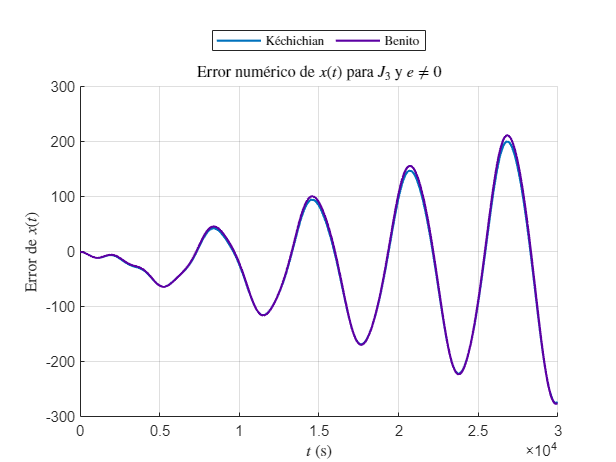

% Resolución
X0 = [x0, y0, z0, dx0, dy0, dz0];

opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);
[~, dXdt] = ode113(@(tOde, X) odeClohessyWiltshireECCJ2J3(tOde, X, 0, J3, R, a, e, n, INC, omega, theta_0), t, X0, opts);
    
% Comparación
plotNumericErrors(   xJ3K',    xJ3B', dXdt(:, 1), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $x(t)$ para $J_3$ y $e \neq 0$', '$t$ (s)',       'Error de $x(t)$', '#0072BD', '#5C00A3');

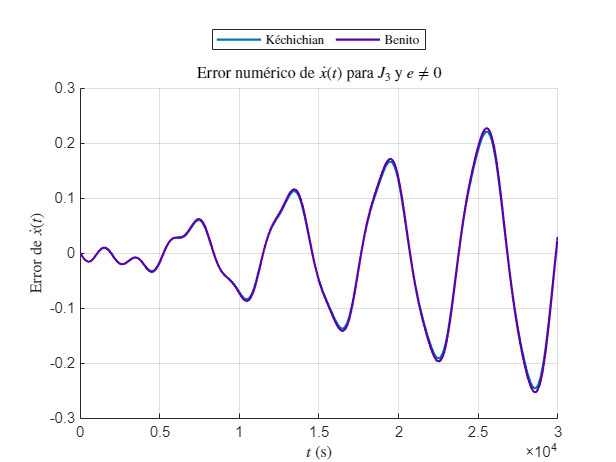

plotNumericErrors(xdotJ3K', xdotJ3B', dXdt(:, 4), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{x}(t)$ para $J_3$ y $e \neq 0$', '$t$ (s)', 'Error de $\dot{x}(t)$', '#0072BD', '#5C00A3');

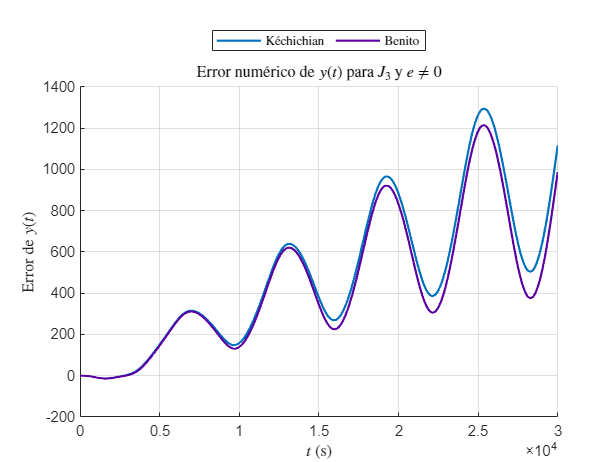

plotNumericErrors(   yJ3K',    yJ3B', dXdt(:, 2), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $y(t)$ para $J_3$ y $e \neq 0$', '$t$ (s)',       'Error de $y(t)$', '#0072BD', '#5C00A3');

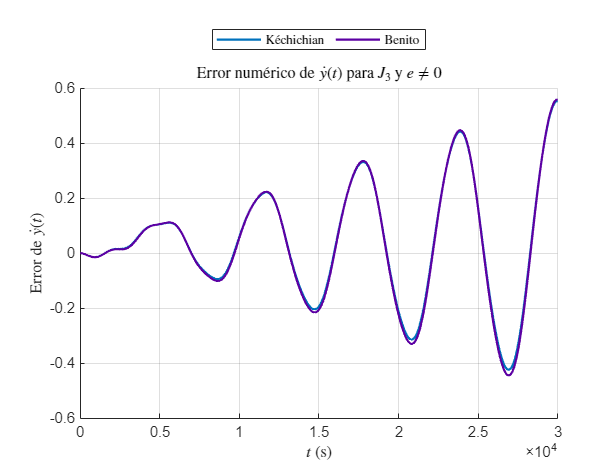

plotNumericErrors(ydotJ3K', ydotJ3B', dXdt(:, 5), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{y}(t)$ para $J_3$ y $e \neq 0$', '$t$ (s)', 'Error de $\dot{y}(t)$', '#0072BD', '#5C00A3');

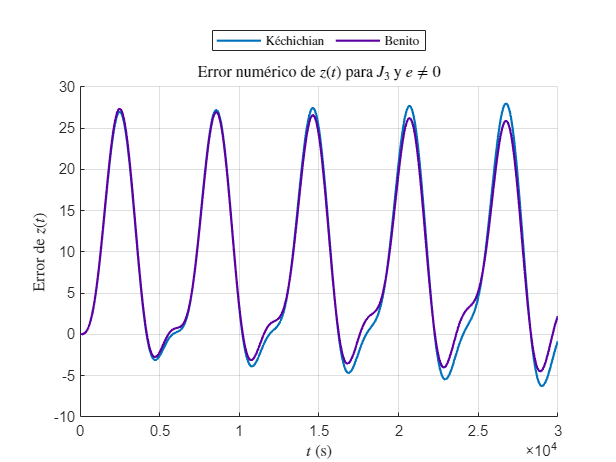

plotNumericErrors(   zJ3K',    zJ3B', dXdt(:, 3), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $z(t)$ para $J_3$ y $e \neq 0$', '$t$ (s)',       'Error de $z(t)$', '#0072BD', '#5C00A3');

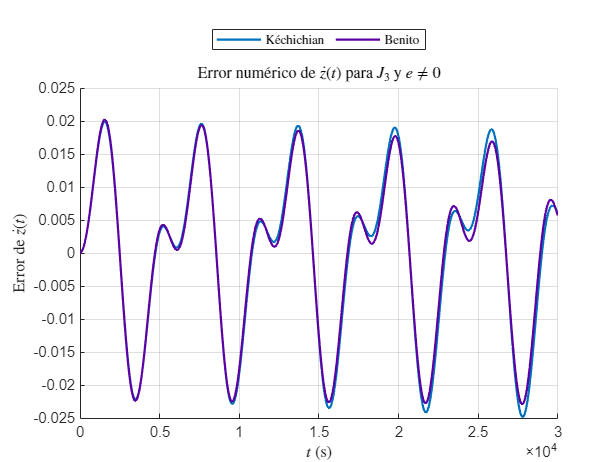

plotNumericErrors(zdotJ3K', zdotJ3B', dXdt(:, 6), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{z}(t)$ para $J_3$ y $e \neq 0$', '$t$ (s)', 'Error de $\dot{z}(t)$', '#0072BD', '#5C00A3');

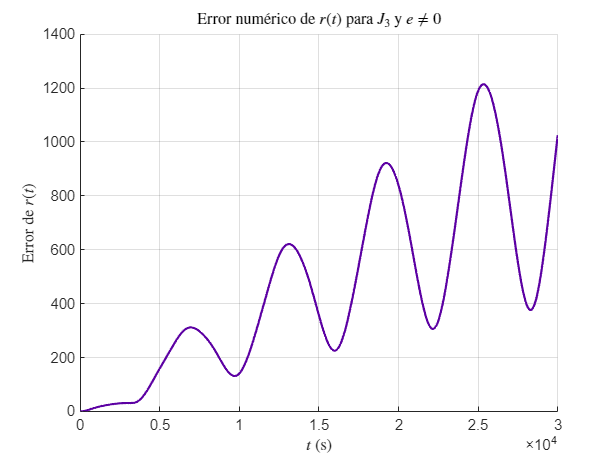


plotNumericErrorNorm([xJ3B', yJ3B', zJ3B'], dXdt(:,1:3), t, 'Error num\''erico de $r(t)$ para $J_3$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $r(t)$', '#5C00A3');

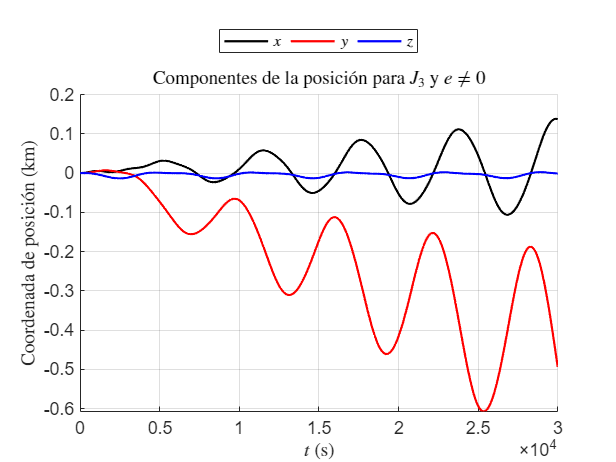




plotMultiComparisons({xJ3B / 10^3, yJ3B / 10^3, zJ3B / 10^3}, t, 'Componentes de la posici\''on para $J_3$ y $e \neq 0$', ...
    {'Coordenada de posici\''on (km)', '$t$ (s)'},  {'$x$', '$y$', '$z$'}, {'k', 'r', 'b'});

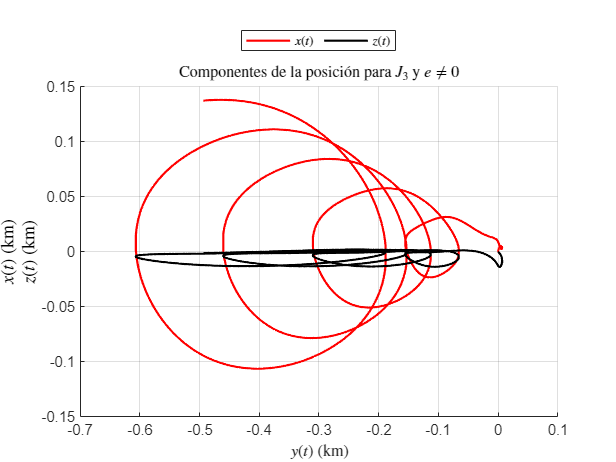

plotComparisons({yJ3B / 10^3, xJ3B / 10^3, zJ3B / 10^3}, {'$y(t)$ (km)', '$x(t)$ (km)', '$z(t)$ (km)'}, ...
   'Componentes de la posici\''on para $J_3$ y $e \neq 0$', {'$x(t)$', '$z(t)$'}, {'r', 'k'});

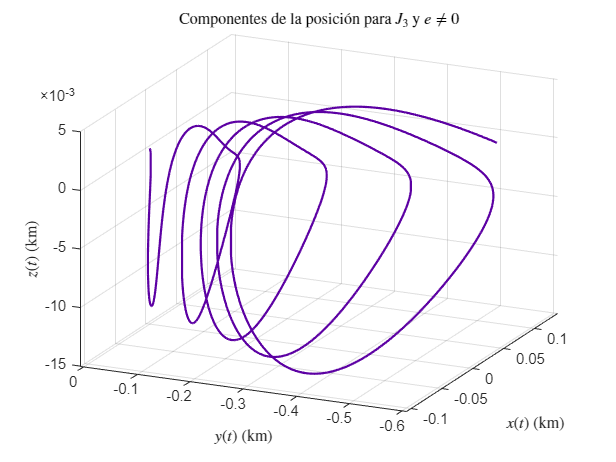

plot3D({xJ3B / 10^3, yJ3B / 10^3, zJ3B / 10^3}, [294.8591 24.6922], ...
    'Componentes de la posici\''on para $J_3$ y $e \neq 0$', ...
    {'$x(t)$ (km)', '$y(t)$ (km)', '$z(t)$ (km)'}, '#5C00A3');